# Machine Learning: Programming Exercise 4

## Neural Networks Learning

In this exercise, you will implement the backpropagation algorithm for neural networks and apply it to the task of hand-written digit recognition.

### Files needed for this exercise

- `ex4.mlx` - MATLAB Live Script that steps you through the exercise

- `ex4data1.mat` - Training set of hand-written digits

- `ex4weights.mat` - Neural network parameters for exercise 4

- `submit.m` - Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `computeNumericalGradient.m` - Numerically compute gradients

- `checkNNGradients.m` - Function to help check your gradients

- `debugInitializeWeights.m` - Function for initializing weights

- `predict.m` - Neural network prediction function

- *`sigmoidGradient.m` - Compute the gradient of the sigmoid function

- *`randInitializeWeights.m` - Randomly initialize weights

- *`nnCostFunction.m` - Neural network cost function

**** indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex4' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                           debugInitializeWeights.m    ex4weights.mat              randInitializeWeights.m     
..                          displayData.m               fmincg.m                    sigmoid.m                   
Machine.m                   ex4.mlx                     lib                         sigmoidGradient.m           
checkNNGradients.m          ex4_companion.mlx           nnCostFunction.m            submit.m                    
computeNumericalGradient.m  ex4data1.mat                predict.m                   



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Neural Networks

In the previous exercise, you implemented feedforward propagation for neural networks and used it to predict handwritten digits with the weights we provided. In this exercise, you will implement the backpropagation algorithm to learn the parameters for the neural network.

### 1.1 Visualizing the data

The code below will load the data and display it on a 2-dimensional plot (Figure 1) by calling the function `displayData`. This is the same dataset that you used in the previous exercise. Run the code below to load the training data into the variables `X` and `y.`

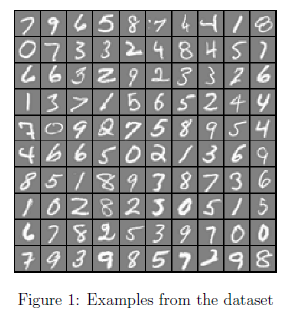

load('ex4data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

    There are 5000 training examples in `ex4data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

### 1.2 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (not counting the extra bias unit which always outputs +1). 

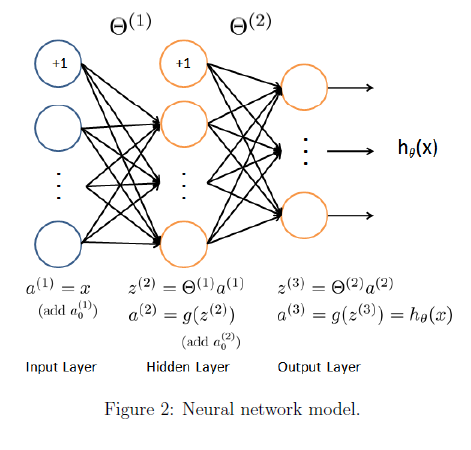

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex4weights.mat. ` Run the code below to load them into `Theta1` and `Theta2`. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

### 1.3 Feedforward and cost function

Now you will implement the cost function and gradient for the neural network. First, complete the code in `nnCostFunction.m` to return the cost. Recall that the cost function for the neural network (without regularization) is


$$J(\theta) =\frac{1}{m}{\sum_{i=1}^m\sum_{k=1}^K{\left[

-y_k^{(i)} \log((h_{\theta}(x^{(i)}))_k)- (1 -y_k^{(i)}) \log(1- (h_{\theta}(x^{(i)}))_k)\right]},$$


where $h_\theta(x^{(i)})$ is computed as shown in the Figure 2 and $K = 10$ is the total number of possible labels. Note that $h_\theta(x^{(i)})_k = a^{(3)}_k$ is the activation (output value) of the $k$-th output unit. Also, recall that whereas the original labels (in the variable `y`) were $1, 2, \ldots, 10,$ for the purpose of training a neural network, we need to recode the labels as vectors containing only values 0 or 1, so that


$$y=\left\lbrack \begin{array}{c}
1\\
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\dots \textrm{or}\;\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack$$


    For example, if $x^{(i)}$ is an image of the digit 5, then the corresponding $y^{(i)}$ (that you should use with the cost function) should be a 10-dimensional vector with $y_5 = 1$, and the other elements equal to 0. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and sum the cost over all examples. Your code should also work for a dataset of any size, with any number of labels (you can assume that there are always at least $K\geq 3$ labels). 

**Implementation Note:** The matrix `X` contains the examples in rows (i.e., `X(i,:)'` is the `i`-th training example $x^{(i)}$, expressed as a $n$ x 1 vector.) When you complete the code in `nnCostFunction.m`, you will need to add the column of 1's to the `X` matrix. The parameters for each unit in the neural network is represented in `Theta1` and `Theta2` as one row. Specifically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. You can use a `for` loop over the examples to compute the cost.  We suggest implementing the feedforward cost *without* regularization first so that it will be easier for you to debug. Later, you will get to implement the regularized cost.

    Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the cost is about 0.287629.

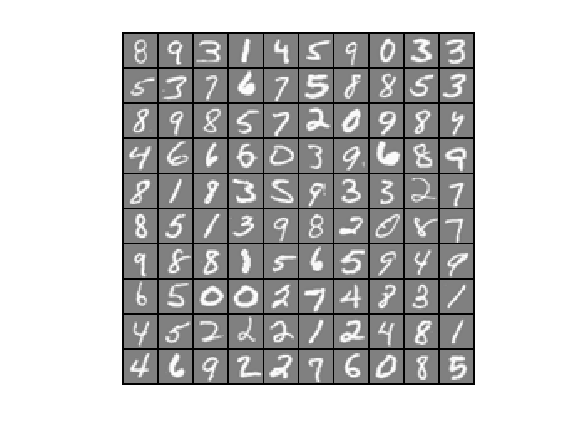

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];


% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

fprintf('Cost at parameters (loaded from ex4weights): %f', J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Regularized cost function

The cost function for neural networks with regularization is given by


$$J(\theta) =
\frac{1}{m}\sum_{i=1}^m
\sum_{k=1}^K 
\left[ -y^{(i)}_k \log((h_{\theta}(x^{(i)})_k)- (1 -y^{(i)}_k) \log(1-(h_{\theta}(x^{(i)}))_k)  \right]
\\ \qquad 
+\frac{\lambda}{2m} \left[\sum_{j=1}^{25} 
\sum_{k=1}^{400} {\left( \Theta_{j,k}^{(1)}\right)^2}+
\sum_{j=1}^{10} 
\sum_{k=1}^{25} {\left( \Theta_{j,k}^{(2)}\right)^2}\right]$$


You can assume that the neural network will only have 3 layers- an input layer, a hidden layer and an output layer. However, your code should work for any number of input units, hidden units and outputs units. While we have explicitly listed the indices above for $\Theta^{(1)}$ and $\Theta^{(2)}$ for clarity, do note that** your code should in general work with **$\Theta^{(1)}$ and $\Theta^{(2)}$ **of any size.**

    Note that you should not be regularizing the terms that correspond to the bias. For the matrices Theta1 and Theta2, this corresponds to the first column of each matrix. You should now add regularization to your cost function. Notice that you can first compute the unregularized cost function $J$ using your existing `nnCostFunction.m` and then later add the cost for the regularization terms. Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`, and $\lambda= 1$. You should see that the cost is about 0.383770.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

*You should now submit your solutions.  Enter/confirm your login and token in the command window when prompted.*

## 2. Backpropagation

In this part of the exercise, you will implement the backpropagation algorithm to compute the gradient for the neural network cost function. You will need to complete the `nnCostFunction.m` so that it returns an appropriate value for `grad`. Once you have computed the gradient, you will be able to train the neural network by minimizing the cost function $J(\theta)$ using an advanced optimizer such as `fmincg`.

    You will first implement the backpropagation algorithm to compute the gradients for the parameters for the (unregularized) neural network. After you have verified that your gradient computation for the unregularized case is correct, you will implement the gradient for the regularized neural network.

### 2.1 Sigmoid gradient

To help you get started with this part of the exercise, you will first implement the sigmoid gradient function. The gradient for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


When you are done, try testing a few values by calling `sigmoidGradient(z)` below. For large values (both positive and negative) of `z`, the gradient should be close to 0. When `z = 0`, the gradient should be exactly 0.25. Your code should also work with vectors and matrices. For a matrix, your function should perform the sigmoid gradient function on every element.

% Call your sigmoidGradient function
sigmoidGradient(0)

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.2 Random initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient. 

Your job is to complete `randInitializeWeights.m` to initialize the weights for $\Theta$; modify the file and fill in the following code:

When you are done, run the code below to call `randInitialWeights` and initialize the neural network parameters.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

*One effective strategy for choosing $\epsilon_{init}$ is to base it on the number of units in the network. A good choice of $\epsilon_{init}$ is $\epsilon_{init} = \frac{\sqrt{6}}{\sqrt{L_{in}+L_{out}}},$ where $L_{in} = s_l$ and $L_{out} = s_{l+1}$ are the number of units in the layers adjacent to $\Theta^{(l)}$.

*You do not need to submit any code for this part of the exercise.*

### 2.3 Backpropagation

Now, you will implement the backpropagation algorithm. Recall that the intuition behind the backpropagation algorithm is as follows. Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

    For an output node, we can directly measure the difference between the network's activation and the true target value, and use that to define $\delta^{(3)}_j$ (since layer 3 is the output layer). For the hidden units, you will compute $\delta^{(l)}_j$ based on a weighted average of the error terms of the nodes in layer $(l + 1)$.

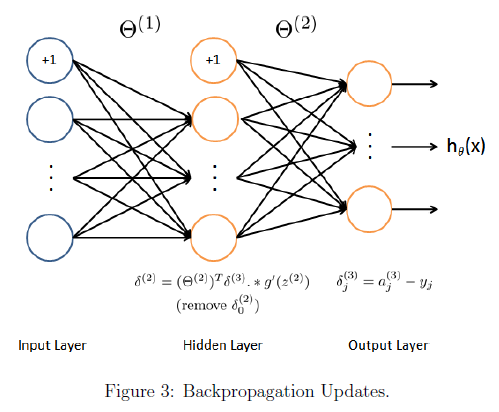

    In detail, here is the backpropagation algorithm (also depicted in Figure 3). You should implement steps 1 to 4 in a loop that processes one example at a time. Concretely, you should implement a `for` loop for `t = 1:m` and place steps 1-4 below inside the `for` loop, with the $t^{th}$ iteration performing the calculation on the $t^{th}$ training example $(x^{(t)}, y^{(t)})$. Step 5 will divide the accumulated gradients by $m$ to obtain the gradients for the neural network cost function.

- Set the input layer's values $(a^{(1)})$ to the $t$-th training example $x^{(t)}$. Perform a feedforward pass (Figure 2), computing the activations $(z^{(2)}, a^{(2)}, z^{(3)}, a^{(3)})$ for layers 2 and 3. Note that you need to add a $+1$ term to ensure that the vectors of activations for layers $a^{(1)}$ and $a^{(2)}$ also include the bias unit. In MATLAB, if `a_1` is a column vector, adding one corresponds to `a_1 = [1; a_1].`

- For each output unit $k$ in layer 3 (the output layer), set $\delta^{(3)}_k = (a_k^{(3)}-y_k)$ where $y_k\in \{0, 1\}$ indicates whether the current training example belongs to class $k$ $(y_k = 1)$, or if it belongs to a different class $(y_k = 0)$.You may find logical arrays helpful for this task (explained in the previous programming exercise).

- For the hidden layer $l = 2$, set $\delta^{(2)} = (\Theta^{(2)})^T \delta^{(3)}.*g'(z^{(2)})$

- Accumulate the gradient from this example using the following formula: $\Delta^{(l)} = \Delta^{(l)} + \delta^{(l+1)} (a^{(l)})^T$. Note that you should skip or remove $\delta_0^{(2)}$. In MATLAB, removing $\delta_0^{(2)}$ corresponds to `delta_2 = delta_2(2:end).`

- Obtain the (unregularized) gradient for the neural network cost function by dividing the accumulated gradients by $\frac{1}{m}:$ $\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij}$

**MATLAB Tip:** You should implement the backpropagation algorithm only after you have successfully completed the feedforward and cost functions. While implementing the backpropagation algorithm, it is often useful to use the size function to print out the sizes of the variables you are working with if you run into dimension mismatch errors (''nonconformant arguments") errors.

    After you have implemented the backpropagation algorithm, the code in the next section will run gradient checking on your implementation. The gradient check will allow you to increase your confidence that your code is computing the gradients correctly.

### 2.4 Gradient checking

In your neural network, you are minimizing the cost function $J(\Theta)$. To perform gradient checking on your parameters, you can imagine 'unrolling' the parameters $\Theta^{(1)},\Theta^{(2)}$ into a long vector $\theta$. By doing so, you can think of the cost function being $J(\theta)$ instead and use the following gradient checking procedure.

    Suppose you have a function $f_i(\theta)$ that purportedly computes $\frac{\partial}{\partial\theta_i}J(\theta)$; you'd like to check if $f_i$ is outputting correct derivative values.


$$\mathrm{Let}\;\theta^{i+} =\theta +\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack \;\mathrm{and}\;\theta^{i-} =\theta -\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack$$


    So, $\theta^{(i+)}$ is the same as $\theta$, except its $i$-th element has been incremented by $\epsilon$. Similarly, $\theta^{(i-)}$is the corresponding vector with the $i$-th element decreased by $\epsilon$. You can now numerically verify $f_i(\theta)$'s correctness by checking, for each $i$, that:


$$f_i(\theta) \approx \frac{J(\theta^{(i+)})-J(\theta^{(i-)})}{2\epsilon}$$


The degree to which these two values should approximate each other will depend on the details of $J$. But assuming $\epsilon= 10^{-4}$, you'll usually find that the left- and right-hand sides of the above will agree to at least 4 signicant digits (and often many more). We have implemented the function to compute the numerical gradient for you in `computeNumericalGradient.m`. While you are not required to modify the file, we highly encourage you to take a look at the code to understand how it works.

   The code below will run the provided function `checkNNGradients.m` which will create a small neural network and dataset that will be used for checking your gradients. If your backpropagation implementation is correct, you should see a relative dierence that is less than 1e-9.

checkNNGradients;

**Practical Tip:** When performing gradient checking, it is much more efficient to use a small neural network with a relatively small number of input units and hidden units, thus having a relatively small number of parameters. Each dimension of $\theta$ requires two evaluations of the cost function and this can be expensive. In the function `checkNNGradients`, our code creates a small random model and dataset which is used with `computeNumericalGradient` for gradient checking. Furthermore, after you are condent that your gradient computations are correct, you should turn off gradient checking before running your learning algorithm.

**Practical Tip: **Gradient checking works for any function where you are computing the cost and the gradient. Concretely, you can use the same `computeNumericalGradient.m` function to check if your gradient implementations for the other exercises are correct too (e.g. logistic regression's cost function). Once your cost function passes the gradient check for the (unregularized) neural network cost function, you should submit the neural network gradient function (backpropagation).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.5 Regularized neural networks

After you have successfully implemeted the backpropagation algorithm, you will add regularization to the gradient. To account for regularization, it turns out that you can add this as an additional term after computing the gradients using backpropagation. Specically, after you have computed $\Delta^{(l)}_{ij}
$ using backpropagation, you should add regularization using


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


Note that you should *not* be regularizing the first column of $\Theta^{(l)}$ which is used for the bias term. Furthermore, in the parameters $\Theta^{(l)}_{ij}$, $i$ is indexed starting from 1, and $j$ is indexed starting from 0. Thus,


$$\Theta^{\left(l\right)} =\left\lbrack \begin{array}{ccc}
\Theta_{1,0}^{\left(l\right)}  & \Theta_{1,1}^{\left(l\right)}  & \cdots \\
\Theta_{2,0}^{\left(l\right)}  & \Theta_{2,1}^{\left(l\right)}  & \;\\
\vdots  & \; & \ddots 
\end{array}\right\rbrack$$


Somewhat confusingly, indexing in MATLAB starts from 1 (for both $i$ and $j$), thus `Theta1(2, 1)` actually corresponds to $\Theta^{(l)}_{2,0}$ (i.e., the entry in the second row, first column of the matrix $\Theta^{(1)}$ shown above)

    Now, modify your code that computes `grad` in `nnCostFunction` to account for regularization. After you are done, run the code below to run gradient checking on your implementation. If your code is correct, you should expect to see a relative difference that is less than 1e-9.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);
% Also output the costFunction debugging value 

Cost at parameters (loaded from ex4weights): 0.287629

% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.6 Learning parameters using `fmincg`

After you have successfully implemented the neural network cost function and gradient computation, run the code below to use `fmincg` to learn a good set of parameters. After the training completes, the code will report the training accuracy of your classifier by computing the percentage of examples it got correct. If your implementation is correct, you should see a reported training accuracy of about 95.3% (this may vary by about 1% due to the random initialization). It is possible to get higher training accuracies by training the neural network for more iterations. 

options = optimset('MaxIter', 50);
lambda = 1;

% Create "short hand" for the cost function to be minimized

Cost at parameters (loaded from ex4weights): 0.383770

costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);
% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

## 3. Visualizing the hidden layer

One way to understand what your neural network is learning is to visualize what the representations captured by the hidden units. Informally, given a particular hidden unit, one way to visualize what it computes is to find an input `x` that will cause it to activate (that is, to have an activation value $(a^{(l)}_i)$close to 1). For the neural network you trained, notice that the $i^{th}$ row of $\Theta^{(1)}$ is a 401-dimensional vector that represents the parameter for the $i^{th}$ hidden unit. If we discard the bias term, we get a 400 dimensional vector that represents the weights from each input pixel to the hidden unit. 

    Thus, one way to visualize the 'representation' captured by the hidden unit is to reshape this 400 dimensional vector into a 20 x 20 image and display it.* 

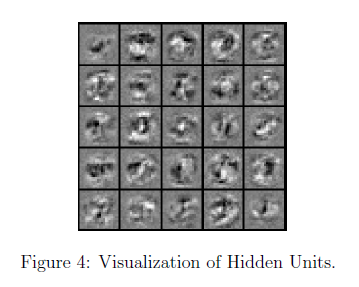

The code below does this by using the `displayData` function and it will show you an image (similar to Figure 4) with 25 units, each corresponding to one hidden unit in the network. In your trained network, you should find that the hidden units corresponds roughly to detectors that look for strokes and other patterns in the input.

% Visualize Weights 
displayData(Theta1(:, 2:end));

ans = 0.2500

**It turns out that this is equivalent to finding the input that gives the highest activation for the hidden unit, given a 'norm' constraint on the input (i.e., *${\left\|x\right\|}_2 \le \;1$*).*

### 3.1 Optional (ungraded) exercise

In this part of the exercise, you will get to try out different learning settings for the neural network to see how the performance of the neural network varies with the regularization parameter and number of training steps (the `MaxIter` option when using `fmincg`). Neural networks are very powerful models that can form highly complex decision boundaries. Without regularization, it is possible for a neural network to 'overfit' a training set so that it obtains close to 100% accuracy on the training set but does not do as well on new examples that it has not seen before. You can set the regularization $\lambda$ to a smaller value and the `MaxIter` parameter to a higher number of iterations to see this for youself. You will also be able to see for yourself the changes in the visualizations of the hidden units when you change the learning parameters $\lambda$ and `MaxIter`.

% Change lambda and MaxIter to see how it affects the result
lambda = 3;
MaxIter = 50;

options = optimset('MaxIter', MaxIter);

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

% Visualize Weights 
displayData(Theta1(:, 2:end));

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

Cost at (fixed) debugging parameters (w/ lambda = 3): 0.576051

Theta1_grad =     0.0417         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0000   -0.0000
    0.0207         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0

Theta2_grad =     0.4187    0.2563    0.2242    0.1670    0.1945    0.2372    0.2408    0.1789    0.2309    0.1793    0.1873    0.2547    0.1753    0.2155    0.1997    0.1967    0.2084    0.1445    0.2151    0.2384    0.1995    0.1926    0.1827    0.1624    0.1958    0.2165
    0.4892    0.2928    0.2576    0.2078    0.2360    0.2791    0.2787    0.2135    0.2745    0.2125    0.2242    0.2957    0.2114    0.2549    0.2386    0.2330    0.2451    0.1802    0.2555    0.2789    0.2323    0.2269    0.2180    0.1974    0.2371    0.2492
    0.4265    0.2551    0.2178    0.1763    0.2039    0.2459    0.2429    0.1874    0.2379    0.1893    0.2045    0.2574    0.1810    0.2203    0.2059    0.2049    0.2124    0.1545    0.2224    0.2348    0.2017    0.1955    0.1886    0.1811    0.1965    0.2196
    0.5181    0.3129    0.2679    0.2147    0.2506    0.3021    0.2959    0.2306    0.2912    0.2279    0.2462    0.3169    0.2260    0.2739    0.2505    0.2500    0.2564    0.1915    0.2748    0.2917   

Theta1_grad =     0.0222         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001
    0.0056         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0

Theta2_grad =     0.3681    0.2214    0.1959    0.1420    0.1630    0.2125    0.2249    0.1582    0.1967    0.1561    0.1487    0.2145    0.1549    0.2069    0.1786    0.1680    0.1847    0.1283    0.1776    0.2046    0.1707    0.1783    0.1550    0.1380    0.1646    0.1938
    0.4315    0.2532    0.2253    0.1796    0.2005    0.2506    0.2597    0.1897    0.2360    0.1861    0.1812    0.2505    0.1880    0.2437    0.2142    0.2006    0.2180    0.1615    0.2135    0.2407    0.1998    0.2099    0.1867    0.1698    0.2019    0.2231
    0.3725    0.2184    0.1879    0.1502    0.1713    0.2188    0.2240    0.1651    0.2024    0.1646    0.1654    0.2160    0.1590    0.2084    0.1827    0.1750    0.1869    0.1369    0.1841    0.1995    0.1718    0.1789    0.1599    0.1556    0.1642    0.1949
    0.4552    0.2698    0.2328    0.1841    0.2119    0.2709    0.2751    0.2047    0.2494    0.1990    0.1993    0.2677    0.2005    0.2616    0.2240    0.2146    0.2267    0.1712    0.2291    0.2502   

Theta1_grad =    -0.0060         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0002
   -0.0153         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0002   -0

Theta2_grad =     0.2714    0.1574    0.1431    0.0968    0.1078    0.1624    0.1849    0.1177    0.1351    0.1125    0.0860    0.1434    0.1150    0.1774    0.1363    0.1161    0.1385    0.0961    0.1130    0.1434    0.1188    0.1452    0.1056    0.0938    0.1095    0.1483
    0.3171    0.1783    0.1631    0.1269    0.1366    0.1902    0.2100    0.1413    0.1645    0.1346    0.1101    0.1685    0.1404    0.2052    0.1630    0.1401    0.1629    0.1228    0.1398    0.1694    0.1394    0.1687    0.1295    0.1186    0.1379    0.1687
    0.2699    0.1516    0.1325    0.1034    0.1146    0.1641    0.1783    0.1217    0.1389    0.1184    0.1021    0.1434    0.1161    0.1728    0.1364    0.1212    0.1376    0.1020    0.1189    0.1361    0.1180    0.1410    0.1093    0.1097    0.1078    0.1459
    0.3286    0.1871    0.1641    0.1261    0.1415    0.2038    0.2192    0.1510    0.1709    0.1420    0.1207    0.1773    0.1477    0.2177    0.1673    0.1478    0.1656    0.1282    0.1480    0.1717   

Theta1_grad =    -0.0177         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0002   -0.0003   -0.0002
   -0.0177         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0002   -0

Theta2_grad =     0.0600    0.0305    0.0339    0.0097    0.0107    0.0397    0.0549    0.0250    0.0183    0.0206   -0.0009    0.0170    0.0234    0.0545    0.0337    0.0162    0.0335    0.0190    0.0071    0.0256    0.0195    0.0447    0.0149    0.0087    0.0109    0.0398
    0.0622    0.0283    0.0325    0.0247    0.0233    0.0390    0.0487    0.0283    0.0284    0.0243    0.0112    0.0234    0.0286    0.0501    0.0356    0.0229    0.0348    0.0275    0.0194    0.0313    0.0232    0.0408    0.0237    0.0197    0.0224    0.0358
    0.0547    0.0252    0.0229    0.0171    0.0188    0.0360    0.0424    0.0264    0.0244    0.0246    0.0150    0.0215    0.0217    0.0432    0.0285    0.0224    0.0301    0.0216    0.0171    0.0198    0.0198    0.0334    0.0204    0.0248    0.0117    0.0341
    0.0528    0.0249    0.0232    0.0156    0.0189    0.0398    0.0435    0.0284    0.0245    0.0220    0.0118    0.0201    0.0266    0.0470    0.0303    0.0208    0.0265    0.0246    0.0174    0.0230   

Iteration     1 | Cost: 3.395712e+00


Theta1_grad =     0.0000         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0

Theta2_grad =    -0.0999   -0.0999   -0.0999   -0.0999   -0.0989   -0.0999   -0.0991   -0.0994   -0.0998   -0.0992   -0.0985   -0.0999   -0.0991   -0.0983   -0.0996   -0.0997   -0.0999   -0.0994   -0.0999   -0.0998   -0.0998   -0.0998   -0.0980   -0.0998   -0.0989   -0.0999
   -0.1000   -0.1000   -0.1000   -0.0999   -0.0999   -0.1000   -0.0998   -0.0999   -0.1000   -0.0999   -0.0997   -0.1000   -0.0999   -0.0993   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.0991   -0.0998   -0.0999   -0.1000
   -0.0999   -0.0999   -0.0999   -0.0999   -0.0999   -0.0999   -0.0997   -0.0999   -0.0999   -0.0999   -0.0995   -0.0999   -0.0999   -0.0988   -0.0999   -0.0999   -0.0999   -0.0999   -0.0999   -0.0999   -0.0999   -0.0999   -0.0984   -0.0997   -0.0998   -0.0999
   -0.0918   -0.0918   -0.0918   -0.0917   -0.0917   -0.0918   -0.0914   -0.0918   -0.0915   -0.0918   -0.0913   -0.0918   -0.0916   -0.0896   -0.0918   -0.0918   -0.0918   -0.0918   -0.0917   -0.0918   

Theta1_grad =     0.0047         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0069         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0

Theta2_grad =    -0.0903   -0.0842   -0.0814   -0.0787   -0.0653   -0.0840   -0.0803   -0.0728   -0.0802   -0.0697   -0.0579   -0.0793   -0.0709   -0.0804   -0.0774   -0.0750   -0.0804   -0.0719   -0.0778   -0.0769   -0.0746   -0.0810   -0.0595   -0.0758   -0.0663   -0.0853
   -0.0894   -0.0880   -0.0878   -0.0749   -0.0733   -0.0878   -0.0848   -0.0821   -0.0815   -0.0811   -0.0576   -0.0844   -0.0791   -0.0840   -0.0866   -0.0812   -0.0866   -0.0829   -0.0772   -0.0832   -0.0817   -0.0868   -0.0570   -0.0700   -0.0761   -0.0881
   -0.0865   -0.0854   -0.0848   -0.0788   -0.0763   -0.0852   -0.0823   -0.0787   -0.0784   -0.0811   -0.0478   -0.0795   -0.0797   -0.0807   -0.0848   -0.0771   -0.0826   -0.0794   -0.0777   -0.0820   -0.0811   -0.0848   -0.0532   -0.0631   -0.0746   -0.0847
   -0.0567   -0.0560   -0.0558   -0.0490   -0.0456   -0.0538   -0.0525   -0.0503   -0.0429   -0.0516   -0.0301   -0.0546   -0.0460   -0.0495   -0.0519   -0.0504   -0.0556   -0.0519   -0.0455   -0.0502   

Theta1_grad =     0.0110         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.0124         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0

Theta2_grad =    -0.0402   -0.0243   -0.0178   -0.0288   -0.0210   -0.0295   -0.0296   -0.0225   -0.0293   -0.0201   -0.0223   -0.0252   -0.0236   -0.0319   -0.0231   -0.0240   -0.0224   -0.0220   -0.0275   -0.0223   -0.0204   -0.0242   -0.0196   -0.0293   -0.0229   -0.0252
   -0.0264   -0.0235   -0.0206   -0.0090   -0.0086   -0.0248   -0.0249   -0.0187   -0.0163   -0.0171   -0.0082   -0.0185   -0.0172   -0.0257   -0.0222   -0.0168   -0.0200   -0.0164   -0.0117   -0.0160   -0.0157   -0.0221   -0.0067   -0.0129   -0.0126   -0.0238
   -0.0279   -0.0253   -0.0242   -0.0184   -0.0145   -0.0260   -0.0265   -0.0180   -0.0176   -0.0184   -0.0017   -0.0162   -0.0228   -0.0270   -0.0268   -0.0145   -0.0196   -0.0183   -0.0146   -0.0240   -0.0192   -0.0258   -0.0076   -0.0054   -0.0204   -0.0223
   -0.0081   -0.0081   -0.0078   -0.0060   -0.0009   -0.0026   -0.0067   -0.0020    0.0008   -0.0046    0.0008   -0.0077   -0.0014   -0.0048   -0.0030   -0.0037   -0.0086   -0.0030   -0.0004   -0.0039   

Theta1_grad =     0.0034         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0002   -0.0001
    0.0033         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0

Theta2_grad =    -0.0068    0.0003    0.0058   -0.0122   -0.0073   -0.0028   -0.0004   -0.0031   -0.0097   -0.0027   -0.0130   -0.0065   -0.0048   -0.0026    0.0000   -0.0066    0.0012   -0.0045   -0.0121   -0.0022   -0.0027    0.0027   -0.0059   -0.0136   -0.0087    0.0018
    0.0067    0.0013    0.0050    0.0075    0.0070    0.0023    0.0035    0.0026    0.0042    0.0025    0.0012    0.0019    0.0032    0.0031    0.0034    0.0022    0.0052    0.0044    0.0038    0.0060    0.0033    0.0049    0.0067    0.0021    0.0040    0.0028
    0.0026   -0.0017   -0.0019   -0.0015    0.0015   -0.0002   -0.0002    0.0020    0.0015    0.0017    0.0064    0.0021   -0.0034   -0.0007   -0.0029    0.0030    0.0032    0.0004    0.0011   -0.0042   -0.0005   -0.0009    0.0046    0.0085   -0.0056    0.0028
    0.0145    0.0078    0.0073    0.0043    0.0087    0.0157    0.0124    0.0119    0.0118    0.0080    0.0060    0.0057    0.0110    0.0147    0.0122    0.0080    0.0074    0.0102    0.0086    0.0086   

Iteration     2 | Cost: 3.230467e+00


Theta1_grad =    -0.0093         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
   -0.0068         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0

Theta2_grad =     0.0105    0.0122    0.0169   -0.0154    0.0077    0.0132    0.0132    0.0156   -0.0013    0.0174   -0.0075   -0.0027    0.0104    0.0098    0.0185   -0.0011    0.0130    0.0133   -0.0157    0.0074    0.0029    0.0187   -0.0032   -0.0183    0.0038    0.0067
   -0.0333   -0.0219   -0.0244   -0.0026   -0.0076   -0.0304   -0.0308   -0.0258   -0.0271   -0.0159   -0.0084   -0.0105   -0.0207   -0.0324   -0.0301   -0.0111   -0.0206   -0.0192   -0.0067   -0.0230   -0.0091   -0.0183   -0.0079   -0.0074   -0.0146   -0.0276
   -0.0052   -0.0063   -0.0041   -0.0050   -0.0062   -0.0081   -0.0064   -0.0023   -0.0061   -0.0070    0.0047    0.0083   -0.0100   -0.0070   -0.0127    0.0047    0.0057    0.0006   -0.0033   -0.0101   -0.0036   -0.0048    0.0049    0.0058   -0.0033   -0.0013
   -0.0652   -0.0490   -0.0473   -0.0233   -0.0281   -0.0476   -0.0569   -0.0474   -0.0333   -0.0415   -0.0147   -0.0365   -0.0358   -0.0540   -0.0434   -0.0277   -0.0512   -0.0394   -0.0180   -0.0387   

Theta1_grad =     0.0010         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.0014         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0

Theta2_grad =    -0.0025    0.0034    0.0086   -0.0135   -0.0033    0.0012    0.0027    0.0018   -0.0087    0.0026   -0.0117   -0.0055   -0.0010    0.0002    0.0050   -0.0052    0.0043    0.0002   -0.0136   -0.0002   -0.0012    0.0070   -0.0054   -0.0153   -0.0053    0.0028
   -0.0064   -0.0067   -0.0046    0.0031    0.0025   -0.0079   -0.0075   -0.0051   -0.0046   -0.0029   -0.0019   -0.0037   -0.0039   -0.0084   -0.0068   -0.0032   -0.0034   -0.0029   -0.0006   -0.0026   -0.0016   -0.0035    0.0019   -0.0020   -0.0020   -0.0073
   -0.0001   -0.0033   -0.0027   -0.0032   -0.0008   -0.0029   -0.0024    0.0009   -0.0008   -0.0010    0.0058    0.0040   -0.0056   -0.0029   -0.0064    0.0034    0.0036    0.0003   -0.0007   -0.0062   -0.0017   -0.0025    0.0045    0.0075   -0.0051    0.0013
   -0.0175   -0.0148   -0.0141   -0.0094   -0.0050   -0.0086   -0.0146   -0.0080   -0.0035   -0.0099   -0.0018   -0.0133   -0.0063   -0.0125   -0.0084   -0.0080   -0.0156   -0.0083   -0.0039   -0.0087   

Iteration     3 | Cost: 3.180124e+00


Theta1_grad =    -0.0007         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
   -0.0008         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0

Theta2_grad =     0.0083    0.0111    0.0159   -0.0140    0.0057    0.0101    0.0111    0.0109   -0.0072    0.0133   -0.0085   -0.0018    0.0057    0.0077    0.0144   -0.0010    0.0110    0.0105   -0.0143    0.0039    0.0033    0.0168   -0.0042   -0.0173    0.0019    0.0062
   -0.0004   -0.0011   -0.0031    0.0071    0.0068   -0.0033   -0.0020   -0.0007   -0.0037    0.0038   -0.0002    0.0006    0.0007   -0.0039   -0.0043    0.0011    0.0008   -0.0003    0.0022   -0.0008    0.0037    0.0044    0.0043    0.0013   -0.0006   -0.0051
    0.0074    0.0017    0.0033   -0.0019   -0.0000    0.0018    0.0042    0.0075    0.0026    0.0011    0.0077    0.0123   -0.0024    0.0036   -0.0045    0.0091    0.0128    0.0069    0.0000   -0.0027    0.0013    0.0038    0.0088    0.0096    0.0009    0.0069
   -0.0119   -0.0133   -0.0129   -0.0073   -0.0035   -0.0022   -0.0096   -0.0059    0.0038   -0.0082   -0.0009   -0.0156   -0.0012   -0.0069   -0.0008   -0.0062   -0.0157   -0.0080   -0.0023   -0.0041   

Theta1_grad =    -0.0062         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
   -0.0065         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0

Theta2_grad =     0.0356    0.0291    0.0332   -0.0105    0.0265    0.0308    0.0321    0.0317    0.0025    0.0354   -0.0002    0.0072    0.0197    0.0271    0.0330    0.0087    0.0249    0.0326   -0.0096    0.0150    0.0141    0.0361    0.0004   -0.0170    0.0175    0.0159
    0.0121    0.0100    0.0007    0.0135    0.0164    0.0059    0.0092    0.0088   -0.0012    0.0169    0.0033    0.0078    0.0090    0.0050   -0.0003    0.0083    0.0082    0.0054    0.0081    0.0028    0.0131    0.0198    0.0083    0.0061    0.0025   -0.0015
    0.0253    0.0127    0.0162    0.0013    0.0051    0.0138    0.0198    0.0230    0.0106    0.0082    0.0119    0.0229    0.0054    0.0184    0.0015    0.0181    0.0293    0.0218    0.0026    0.0060    0.0075    0.0169    0.0159    0.0126    0.0134    0.0178
    0.0005   -0.0092   -0.0091   -0.0029    0.0008    0.0111    0.0013   -0.0004    0.0174   -0.0036    0.0013   -0.0187    0.0081    0.0049    0.0135   -0.0024   -0.0156   -0.0057    0.0016    0.0053   

Theta1_grad =    -0.0148         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
   -0.0153         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0

Theta2_grad =     0.0848    0.0592    0.0629    0.0042    0.0604    0.0644    0.0695    0.0654    0.0300    0.0654    0.0155    0.0222    0.0387    0.0632    0.0547    0.0246    0.0434    0.0645    0.0112    0.0367    0.0328    0.0575    0.0110   -0.0076    0.0401    0.0363
    0.0286    0.0244    0.0074    0.0195    0.0297    0.0170    0.0235    0.0213    0.0029    0.0323    0.0081    0.0148    0.0176    0.0156    0.0038    0.0150    0.0156    0.0134    0.0162    0.0074    0.0228    0.0344    0.0122    0.0103    0.0065    0.0019
    0.0527    0.0276    0.0339    0.0059    0.0194    0.0325    0.0426    0.0466    0.0222    0.0221    0.0183    0.0279    0.0178    0.0389    0.0131    0.0247    0.0421    0.0435    0.0075    0.0198    0.0151    0.0315    0.0220    0.0150    0.0298    0.0292
    0.0191   -0.0005   -0.0009    0.0034    0.0096    0.0286    0.0169    0.0094    0.0322    0.0045    0.0051   -0.0194    0.0180    0.0212    0.0276    0.0036   -0.0144    0.0011    0.0083    0.0168   

Iteration     4 | Cost: 2.839368e+00


Theta1_grad =    -0.0098         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0068         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0

Theta2_grad =     0.0653    0.0483    0.0512    0.0103    0.0535    0.0447    0.0527    0.0483    0.0264    0.0501    0.0152    0.0199    0.0243    0.0494    0.0321    0.0211    0.0309    0.0539    0.0214    0.0252    0.0288    0.0392    0.0067   -0.0042    0.0335    0.0288
    0.0071    0.0147   -0.0094    0.0159    0.0201    0.0005    0.0072    0.0077   -0.0142    0.0256    0.0040    0.0114    0.0102   -0.0039   -0.0109    0.0097    0.0058   -0.0025    0.0112   -0.0069    0.0187    0.0268    0.0075    0.0075   -0.0073   -0.0151
    0.0193    0.0035    0.0119   -0.0072    0.0000    0.0073    0.0160    0.0301    0.0003   -0.0005    0.0100    0.0158    0.0050    0.0112   -0.0050    0.0122    0.0256    0.0306   -0.0111    0.0043   -0.0015    0.0147    0.0131    0.0072    0.0250    0.0087
    0.0320    0.0110    0.0099    0.0097    0.0168    0.0395    0.0277    0.0148    0.0375    0.0099    0.0083   -0.0189    0.0201    0.0317    0.0285    0.0113   -0.0124    0.0103    0.0157    0.0226   

Iteration     5 | Cost: 2.438647e+00


Theta1_grad =     0.0149         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0001    0.0001
    0.0259         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0

Theta2_grad =    -0.0627   -0.0387   -0.0353   -0.0556   -0.0126   -0.0452   -0.0558   -0.0307   -0.0612   -0.0059   -0.0239   -0.0234   -0.0215   -0.0602   -0.0114   -0.0214   -0.0229   -0.0119   -0.0581   -0.0459   -0.0270   -0.0126   -0.0347   -0.0527   -0.0153   -0.0572
   -0.0178   -0.0093   -0.0266    0.0088    0.0073   -0.0181   -0.0156   -0.0108   -0.0267    0.0103   -0.0021    0.0024   -0.0006   -0.0206   -0.0245    0.0019   -0.0085   -0.0191    0.0001   -0.0188    0.0080    0.0140    0.0025    0.0032   -0.0181   -0.0285
   -0.0302   -0.0311   -0.0240   -0.0216   -0.0345   -0.0315   -0.0277   -0.0094   -0.0234   -0.0329   -0.0006    0.0079   -0.0242   -0.0292   -0.0366    0.0023    0.0101   -0.0042   -0.0276   -0.0268   -0.0199   -0.0137    0.0044    0.0021    0.0013   -0.0183
   -0.0459   -0.0464   -0.0484   -0.0164   -0.0302   -0.0171   -0.0403   -0.0411    0.0045   -0.0379   -0.0117   -0.0515   -0.0081   -0.0367   -0.0004   -0.0139   -0.0534   -0.0445   -0.0166   -0.0147   

Theta1_grad =     0.0006         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0074         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0

Theta2_grad =    -0.0049    0.0019    0.0040   -0.0222    0.0126   -0.0008   -0.0046    0.0056   -0.0183    0.0163   -0.0065   -0.0018    0.0017   -0.0079    0.0100   -0.0023    0.0034    0.0155   -0.0195   -0.0096   -0.0017    0.0110   -0.0143   -0.0272    0.0061   -0.0145
   -0.0042    0.0044   -0.0170    0.0128    0.0138   -0.0074   -0.0028   -0.0004   -0.0196    0.0185    0.0010    0.0079    0.0059   -0.0106   -0.0166    0.0061   -0.0000   -0.0100    0.0063   -0.0117    0.0139    0.0217    0.0052    0.0056   -0.0122   -0.0208
   -0.0039   -0.0116   -0.0041   -0.0133   -0.0172   -0.0099   -0.0036    0.0121   -0.0100   -0.0159    0.0046    0.0123   -0.0076   -0.0062   -0.0188    0.0075    0.0193    0.0144   -0.0185   -0.0089   -0.0097    0.0029    0.0090    0.0048    0.0139   -0.0024
   -0.0072   -0.0166   -0.0186   -0.0027   -0.0088    0.0137   -0.0050   -0.0126    0.0215   -0.0143   -0.0026   -0.0338    0.0074   -0.0002    0.0156   -0.0015   -0.0313   -0.0170   -0.0004    0.0059   

Iteration     6 | Cost: 2.340916e+00


Theta1_grad =     0.0068         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0116         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0

Theta2_grad =    -0.0137   -0.0039    0.0000   -0.0237    0.0060   -0.0075   -0.0120   -0.0003   -0.0222    0.0093   -0.0105   -0.0070   -0.0038   -0.0152    0.0045   -0.0058   -0.0003    0.0087   -0.0214   -0.0142   -0.0055    0.0061   -0.0171   -0.0287    0.0005   -0.0185
    0.0025    0.0048   -0.0120    0.0145    0.0174   -0.0005    0.0031    0.0077   -0.0149    0.0199    0.0020    0.0069    0.0098   -0.0047   -0.0109    0.0054    0.0029   -0.0057    0.0044   -0.0050    0.0142    0.0216    0.0074    0.0063   -0.0084   -0.0160
    0.0059   -0.0056    0.0017   -0.0149   -0.0103   -0.0022    0.0051    0.0227   -0.0027   -0.0074    0.0068    0.0153   -0.0025    0.0022   -0.0103    0.0086    0.0187    0.0198   -0.0160   -0.0029   -0.0073    0.0068    0.0113    0.0058    0.0123    0.0034
    0.0135    0.0047    0.0001    0.0037    0.0069    0.0254    0.0121    0.0001    0.0246    0.0016    0.0050   -0.0165    0.0117    0.0155    0.0185    0.0093   -0.0136    0.0001    0.0081    0.0101   

Theta1_grad =     0.0143         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0160         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

Theta2_grad =    -0.0170   -0.0067    0.0002   -0.0230    0.0027   -0.0098   -0.0145   -0.0022   -0.0231    0.0055   -0.0138   -0.0119   -0.0075   -0.0178    0.0014   -0.0081   -0.0015    0.0054   -0.0213   -0.0160   -0.0076    0.0039   -0.0189   -0.0292   -0.0026   -0.0194
    0.0096    0.0061   -0.0073    0.0145    0.0161    0.0070    0.0088    0.0138   -0.0103    0.0186    0.0035    0.0037    0.0146    0.0014   -0.0038    0.0043    0.0059   -0.0013    0.0009    0.0022    0.0142    0.0206    0.0100    0.0066   -0.0047   -0.0110
    0.0253    0.0105    0.0131   -0.0063    0.0012    0.0120    0.0218    0.0271    0.0092    0.0060    0.0122    0.0215    0.0094    0.0183    0.0064    0.0113    0.0202    0.0262   -0.0031    0.0119    0.0023    0.0152    0.0164    0.0076    0.0126    0.0128
    0.0505    0.0419    0.0316    0.0249    0.0267    0.0346    0.0424    0.0133    0.0314    0.0249    0.0230    0.0229    0.0209    0.0404    0.0254    0.0297    0.0161    0.0265    0.0303    0.0211   

Iteration     7 | Cost: 2.031691e+00


Theta1_grad =     0.0064         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0068         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0

Theta2_grad =     0.0290    0.0301    0.0216    0.0184    0.0090    0.0155    0.0222    0.0094    0.0156    0.0097    0.0091    0.0164    0.0127    0.0235    0.0199    0.0085    0.0115    0.0126    0.0222    0.0199    0.0172    0.0144    0.0104   -0.0019    0.0073    0.0142
    0.0158    0.0085   -0.0048    0.0114    0.0087    0.0139    0.0131    0.0183   -0.0051    0.0128    0.0047    0.0027    0.0201    0.0080    0.0052    0.0022    0.0093    0.0029   -0.0031    0.0097    0.0122    0.0146    0.0136    0.0053   -0.0025   -0.0054
    0.0234    0.0119    0.0108    0.0007    0.0001    0.0127    0.0194    0.0214    0.0112    0.0057    0.0109    0.0187    0.0107    0.0175    0.0110    0.0081    0.0103    0.0168    0.0056    0.0163    0.0033    0.0129    0.0192    0.0066    0.0057    0.0123
   -0.0455   -0.0427   -0.0385   -0.0339   -0.0074   -0.0028   -0.0359   -0.0242   -0.0048   -0.0153   -0.0196   -0.0477   -0.0149   -0.0309   -0.0074   -0.0093   -0.0430   -0.0283   -0.0338   -0.0303   

Iteration     8 | Cost: 1.829924e+00


Theta1_grad =    -0.0112         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0285         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0

Theta2_grad =     0.0194    0.0211    0.0076    0.0145    0.0023    0.0075    0.0123    0.0096    0.0099    0.0058    0.0109    0.0118    0.0062    0.0118    0.0143    0.0050    0.0060    0.0062    0.0179    0.0142    0.0108    0.0097    0.0136   -0.0017    0.0022    0.0052
   -0.0439   -0.0333   -0.0209   -0.0259   -0.0005   -0.0213   -0.0270   -0.0137   -0.0373   -0.0024   -0.0328   -0.0365   -0.0160   -0.0387   -0.0376   -0.0117   -0.0056   -0.0178   -0.0461   -0.0370   -0.0088   -0.0020   -0.0238   -0.0090   -0.0170   -0.0332
   -0.0351   -0.0311   -0.0069   -0.0366   -0.0089   -0.0258   -0.0219    0.0012   -0.0186   -0.0146   -0.0161   -0.0100   -0.0304   -0.0241   -0.0338   -0.0046   -0.0007    0.0000   -0.0357   -0.0337   -0.0268   -0.0099   -0.0145   -0.0040   -0.0062   -0.0070
   -0.0106   -0.0090   -0.0100   -0.0118    0.0020    0.0032   -0.0072   -0.0097    0.0010    0.0002   -0.0028   -0.0132   -0.0026   -0.0068   -0.0004    0.0061   -0.0145   -0.0047   -0.0119   -0.0130   

Iteration     9 | Cost: 1.662148e+00


Theta1_grad =     0.0035         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0002    0.0001
    0.0050         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0

Theta2_grad =    -0.0134   -0.0014    0.0013   -0.0140   -0.0011   -0.0087   -0.0075   -0.0043   -0.0133    0.0006   -0.0132   -0.0125   -0.0123   -0.0119   -0.0045   -0.0087   -0.0002    0.0011   -0.0133   -0.0121   -0.0058    0.0010   -0.0138   -0.0196   -0.0086   -0.0084
   -0.0069   -0.0063   -0.0044   -0.0093    0.0002    0.0022   -0.0050    0.0067   -0.0111   -0.0007   -0.0085   -0.0084    0.0023   -0.0077   -0.0091   -0.0065    0.0048   -0.0038   -0.0121   -0.0098   -0.0020    0.0002   -0.0005   -0.0001   -0.0060   -0.0081
   -0.0340   -0.0303   -0.0084   -0.0340   -0.0046   -0.0197   -0.0194   -0.0000   -0.0201   -0.0174   -0.0243   -0.0165   -0.0237   -0.0209   -0.0306   -0.0072   -0.0019   -0.0015   -0.0339   -0.0319   -0.0270   -0.0069   -0.0139   -0.0033   -0.0088   -0.0085
    0.0259    0.0239    0.0107    0.0178    0.0037    0.0049    0.0181    0.0135    0.0083    0.0178    0.0248    0.0227    0.0052    0.0048    0.0056    0.0201    0.0156    0.0134    0.0220    0.0072   

Iteration    10 | Cost: 1.480869e+00


Theta1_grad =     0.0035         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0251         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0

Theta2_grad =    -0.0188   -0.0062   -0.0003   -0.0186   -0.0011   -0.0092   -0.0072   -0.0059   -0.0174   -0.0007   -0.0178   -0.0156   -0.0141   -0.0145   -0.0094   -0.0090   -0.0006    0.0001   -0.0187   -0.0177   -0.0091   -0.0002   -0.0177   -0.0199   -0.0113   -0.0112
    0.0940    0.0697    0.0389    0.0601    0.0012    0.0422    0.0421    0.0669    0.0668    0.0167    0.0766    0.0647    0.0342    0.0714    0.0622    0.0110    0.0341    0.0321    0.0887    0.0678    0.0276    0.0067    0.0578    0.0211    0.0332    0.0651
    0.0546    0.0430    0.0149    0.0517    0.0049    0.0191    0.0295    0.0275    0.0377    0.0265    0.0304    0.0146    0.0266    0.0328    0.0463    0.0102    0.0020    0.0105    0.0545    0.0542    0.0415    0.0272    0.0333    0.0043    0.0042    0.0173
   -0.0323   -0.0277   -0.0219   -0.0303   -0.0010    0.0002   -0.0223   -0.0191   -0.0117   -0.0170   -0.0255   -0.0312   -0.0039   -0.0136   -0.0067   -0.0026   -0.0228   -0.0157   -0.0321   -0.0317   

Theta1_grad =     0.0021         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0001
    0.0130         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0

Theta2_grad =    -0.0163   -0.0039    0.0004   -0.0164   -0.0011   -0.0091   -0.0077   -0.0052   -0.0153   -0.0001   -0.0156   -0.0144   -0.0132   -0.0132   -0.0069   -0.0091   -0.0005    0.0005   -0.0161   -0.0149   -0.0075    0.0003   -0.0160   -0.0199   -0.0099   -0.0096
    0.0362    0.0261    0.0146    0.0184    0.0007    0.0211    0.0174    0.0326    0.0214    0.0059    0.0278    0.0245    0.0153    0.0257    0.0209    0.0024    0.0183    0.0131    0.0304    0.0206    0.0097    0.0033    0.0251    0.0094    0.0104    0.0218
    0.0039    0.0013    0.0010    0.0025    0.0006    0.0000    0.0038    0.0115    0.0028    0.0006   -0.0019   -0.0018   -0.0011    0.0015    0.0025    0.0008    0.0001    0.0035    0.0038    0.0041    0.0019    0.0084    0.0067    0.0003   -0.0034   -0.0004
   -0.0061   -0.0043   -0.0061   -0.0080    0.0002    0.0018   -0.0045   -0.0036   -0.0012   -0.0010   -0.0030   -0.0071    0.0001   -0.0045   -0.0007    0.0046   -0.0060   -0.0033   -0.0071   -0.0102   

Iteration    11 | Cost: 1.364458e+00


Theta1_grad =    -0.0004         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0001
   -0.0155         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0

Theta2_grad =    -0.0047    0.0012    0.0007   -0.0052   -0.0006   -0.0031   -0.0013   -0.0003   -0.0043    0.0008   -0.0046   -0.0054   -0.0068   -0.0036   -0.0000   -0.0035    0.0003    0.0008   -0.0046   -0.0044   -0.0025    0.0007   -0.0053   -0.0101   -0.0042   -0.0019
   -0.0184   -0.0138   -0.0061   -0.0167   -0.0001   -0.0034   -0.0090   -0.0011   -0.0150   -0.0070   -0.0174   -0.0147   -0.0052   -0.0127   -0.0166   -0.0077    0.0016   -0.0082   -0.0196   -0.0205   -0.0070   -0.0027   -0.0072   -0.0007   -0.0082   -0.0135
    0.0368    0.0287    0.0074    0.0344    0.0033    0.0143    0.0179    0.0228    0.0193    0.0180    0.0160    0.0087    0.0218    0.0167    0.0291    0.0072    0.0014    0.0071    0.0367    0.0365    0.0287    0.0235    0.0256    0.0030    0.0018    0.0081
    0.0164    0.0161    0.0066    0.0104    0.0005    0.0034    0.0096    0.0129    0.0042    0.0093    0.0156    0.0139    0.0056    0.0024    0.0030    0.0103    0.0112    0.0055    0.0150    0.0059   

Iteration    12 | Cost: 1.281460e+00


Theta1_grad =     0.0158         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
   -0.0253         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0001    0.0000    0

Theta2_grad =     0.0102    0.0082    0.0014    0.0085    0.0001    0.0032    0.0036    0.0065    0.0088    0.0025    0.0081    0.0026    0.0031    0.0044    0.0017    0.0048    0.0006    0.0010    0.0102    0.0097    0.0066    0.0017    0.0079   -0.0007    0.0012    0.0068
   -0.0365   -0.0267   -0.0138   -0.0240   -0.0001   -0.0101   -0.0179   -0.0206   -0.0248   -0.0123   -0.0299   -0.0232   -0.0154   -0.0199   -0.0148   -0.0141   -0.0035   -0.0173   -0.0365   -0.0358   -0.0132   -0.0072   -0.0181   -0.0015   -0.0132   -0.0275
   -0.0139   -0.0128   -0.0051   -0.0136   -0.0005   -0.0044   -0.0074   -0.0015   -0.0064   -0.0125   -0.0097   -0.0056   -0.0105   -0.0038   -0.0069   -0.0043   -0.0009   -0.0017   -0.0139   -0.0135   -0.0123   -0.0047   -0.0035    0.0003   -0.0029   -0.0051
   -0.0007    0.0009   -0.0017   -0.0038   -0.0004    0.0025   -0.0022    0.0024    0.0006   -0.0033    0.0001   -0.0012    0.0032   -0.0003    0.0004    0.0028    0.0006   -0.0036   -0.0010   -0.0053   

Theta1_grad = 25×401
    0.0058         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0197         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000
    0.0144         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0022         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0064    0.0064    0.0012    0.0052   -0.0000    0.0017    0.0029    0.0045    0.0054    0.0020    0.0053    0.0014    0.0003    0.0031    0.0027    0.0023    0.0007    0.0010    0.0064    0.0060    0.0040    0.0015    0.0047   -0.0025    0.0000    0.0042
   -0.0290   -0.0212   -0.0102   -0.0216   -0.0002   -0.0075   -0.0140   -0.0117   -0.0208   -0.0099   -0.0252   -0.0204   -0.0108   -0.0174   -0.0178   -0.0110   -0.0017   -0.0131   -0.0293   -0.0291   -0.0106   -0.0050   -0.0139   -0.0016   -0.0112   -0.0211
    0.0094    0.0071    0.0012    0.0085    0.0008    0.0037    0.0038    0.0123    0.0048    0.0021   -0.0002   -0.0012    0.0056    0.0043    0.0065    0.0015   -0.0002    0.0016    0.0094    0.0096    0.0075    0.0092    0.0094    0.0010   -0.0010    0.0014
    0.0087    0.0094    0.0033    0.0038   -0.0002    0.0031    0.0043    0.0102    0.0024    0.0033    0.0079    0.0068    0.0053    0.0010    0.0012    0.0069    0.0067    0.0009    0.0080    0.0

Iteration    13 | Cost: 1.223385e+00


Theta1_grad = 25×401
    0.0049         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0069         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000
    0.0127         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0003         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0068    0.0064    0.0014    0.0056    0.0000    0.0018    0.0035    0.0047    0.0060    0.0020    0.0057    0.0013    0.0004    0.0035    0.0023    0.0028    0.0006    0.0011    0.0068    0.0064    0.0043    0.0013    0.0050   -0.0022    0.0001    0.0045
   -0.0127   -0.0087   -0.0043   -0.0110   -0.0001   -0.0010   -0.0073   -0.0019   -0.0109   -0.0057   -0.0125   -0.0092   -0.0037   -0.0075   -0.0090   -0.0077    0.0021   -0.0068   -0.0133   -0.0157   -0.0054   -0.0027   -0.0043    0.0005   -0.0056   -0.0096
   -0.0005   -0.0011   -0.0011   -0.0009    0.0002    0.0001   -0.0008    0.0076   -0.0003   -0.0036   -0.0051   -0.0036   -0.0009    0.0004   -0.0001   -0.0010   -0.0006    0.0001   -0.0005   -0.0001   -0.0005    0.0042    0.0038    0.0005   -0.0021   -0.0016
   -0.0028   -0.0009   -0.0033   -0.0052   -0.0004    0.0022   -0.0031    0.0010   -0.0000   -0.0028   -0.0009   -0.0034    0.0022   -0.0013    0.0002    0.0031   -0.0014   -0.0040   -0.0032   -0.0

Iteration    14 | Cost: 1.135034e+00


Theta1_grad = 25×401
   -0.0093         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0040         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000
   -0.0010         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0013         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0073   -0.0024   -0.0005   -0.0073   -0.0004   -0.0031   -0.0020   -0.0022   -0.0061    0.0000   -0.0063   -0.0062   -0.0054   -0.0045   -0.0009   -0.0038   -0.0005    0.0001   -0.0072   -0.0067   -0.0035   -0.0002   -0.0066   -0.0081   -0.0047   -0.0033
    0.0315    0.0229    0.0146    0.0141    0.0003    0.0198    0.0161    0.0273    0.0193    0.0049    0.0225    0.0176    0.0149    0.0203    0.0131    0.0033    0.0136    0.0109    0.0293    0.0201    0.0075    0.0021    0.0178    0.0060    0.0099    0.0201
    0.0171    0.0138    0.0049    0.0151    0.0011    0.0078    0.0097    0.0155    0.0100    0.0061    0.0041    0.0004    0.0103    0.0080    0.0127    0.0030    0.0002    0.0022    0.0171    0.0173    0.0136    0.0118    0.0112    0.0012   -0.0001    0.0026
    0.0008    0.0024   -0.0009   -0.0018   -0.0003    0.0022    0.0008    0.0038    0.0012    0.0009    0.0023   -0.0004    0.0019   -0.0009   -0.0000    0.0053    0.0014   -0.0009    0.0004   -0.0

Theta1_grad = 25×401
   -0.0039         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000
    0.0044         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0010         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0018    0.0008    0.0003   -0.0023   -0.0002   -0.0010    0.0004    0.0001   -0.0012    0.0008   -0.0014   -0.0033   -0.0032   -0.0013    0.0006   -0.0010   -0.0000    0.0005   -0.0017   -0.0016   -0.0005    0.0003   -0.0023   -0.0057   -0.0027   -0.0003
    0.0121    0.0094    0.0060    0.0038    0.0001    0.0102    0.0052    0.0150    0.0061    0.0001    0.0071    0.0063    0.0067    0.0083    0.0023   -0.0017    0.0082    0.0031    0.0107    0.0046    0.0021    0.0002    0.0090    0.0036    0.0029    0.0079
    0.0105    0.0084    0.0024    0.0094    0.0008    0.0048    0.0054    0.0128    0.0060    0.0025    0.0004   -0.0010    0.0063    0.0051    0.0076    0.0014   -0.0001    0.0012    0.0105    0.0108    0.0086    0.0093    0.0088    0.0009   -0.0009    0.0011
   -0.0003    0.0014   -0.0016   -0.0029   -0.0003    0.0022   -0.0005    0.0031    0.0008   -0.0004    0.0013   -0.0012    0.0021   -0.0010    0.0001    0.0045    0.0005   -0.0020   -0.0007   -0.0

Iteration    15 | Cost: 1.096922e+00


Theta1_grad = 25×401
    0.0040         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0027         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000
    0.0042         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0006         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0078   -0.0032   -0.0006   -0.0077   -0.0004   -0.0032   -0.0025   -0.0030   -0.0066   -0.0000   -0.0065   -0.0060   -0.0053   -0.0048   -0.0009   -0.0039   -0.0005    0.0000   -0.0077   -0.0072   -0.0039   -0.0003   -0.0071   -0.0082   -0.0042   -0.0032
   -0.0032   -0.0021   -0.0014   -0.0028   -0.0000    0.0032   -0.0031    0.0041   -0.0042   -0.0016   -0.0054   -0.0040    0.0005   -0.0014   -0.0044   -0.0054    0.0024   -0.0032   -0.0040   -0.0063   -0.0016   -0.0010    0.0007    0.0011   -0.0033   -0.0029
   -0.0119   -0.0106   -0.0051   -0.0114   -0.0006   -0.0051   -0.0081    0.0030   -0.0076   -0.0095   -0.0101   -0.0048   -0.0089   -0.0053   -0.0094   -0.0042   -0.0010   -0.0016   -0.0118   -0.0113   -0.0095   -0.0003   -0.0009    0.0002   -0.0033   -0.0048
   -0.0043   -0.0026   -0.0041   -0.0055   -0.0004    0.0018   -0.0027   -0.0002    0.0003   -0.0008   -0.0011   -0.0048    0.0002   -0.0017   -0.0006    0.0034   -0.0025   -0.0031   -0.0045   -0.0

Iteration    16 | Cost: 1.045772e+00


Theta1_grad = 25×401
    0.0012         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0059         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0050         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0011         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0043   -0.0015   -0.0003   -0.0045   -0.0002   -0.0018   -0.0009   -0.0010   -0.0035    0.0004   -0.0033   -0.0039   -0.0032   -0.0027   -0.0001   -0.0019   -0.0003    0.0002   -0.0042   -0.0039   -0.0019   -0.0000   -0.0041   -0.0058   -0.0029   -0.0016
   -0.0022   -0.0016   -0.0017   -0.0006    0.0000    0.0032   -0.0024    0.0047   -0.0029   -0.0010   -0.0048   -0.0042    0.0006   -0.0006   -0.0038   -0.0047    0.0010   -0.0033   -0.0029   -0.0042   -0.0006   -0.0006    0.0013    0.0013   -0.0034   -0.0028
    0.0025    0.0019    0.0000    0.0011    0.0001    0.0020    0.0014    0.0081    0.0009   -0.0026   -0.0029   -0.0015    0.0014    0.0014    0.0011   -0.0006   -0.0004   -0.0000    0.0026    0.0029    0.0019    0.0051    0.0056    0.0010   -0.0012   -0.0011
   -0.0016   -0.0003   -0.0022   -0.0036   -0.0003    0.0017   -0.0002    0.0021    0.0016    0.0012    0.0009   -0.0028    0.0001   -0.0011   -0.0007    0.0049   -0.0004   -0.0017   -0.0018   -0.0

Iteration    17 | Cost: 9.922327e-01


Theta1_grad = 25×401
    0.0023         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0103         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000
    0.0006         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0009         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0025   -0.0008   -0.0002   -0.0028   -0.0001   -0.0011   -0.0003   -0.0006   -0.0021    0.0006   -0.0017   -0.0027   -0.0018   -0.0017    0.0003   -0.0006   -0.0002    0.0002   -0.0025   -0.0023   -0.0007    0.0002   -0.0025   -0.0043   -0.0022   -0.0008
    0.0220    0.0166    0.0115    0.0094    0.0002    0.0153    0.0152    0.0168    0.0155    0.0050    0.0111    0.0060    0.0124    0.0132    0.0100    0.0025    0.0056    0.0052    0.0209    0.0172    0.0088    0.0022    0.0123    0.0045    0.0033    0.0105
   -0.0000   -0.0004   -0.0012   -0.0015    0.0000    0.0008   -0.0006    0.0064   -0.0009   -0.0035   -0.0032   -0.0013   -0.0004    0.0002   -0.0012   -0.0008   -0.0004   -0.0002    0.0000    0.0004   -0.0000    0.0039    0.0045    0.0012   -0.0011   -0.0014
   -0.0052   -0.0036   -0.0050   -0.0055   -0.0003    0.0013   -0.0031   -0.0003    0.0003    0.0001   -0.0015   -0.0059   -0.0012   -0.0017   -0.0013    0.0033   -0.0034   -0.0035   -0.0054   -0.0

Iteration    18 | Cost: 9.492212e-01


Theta1_grad = 25×401
    0.0046         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0134         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000
   -0.0048         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0022         0         0    0.0000    0.0000    0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0031   -0.0017   -0.0008   -0.0028   -0.0000   -0.0010   -0.0010   -0.0009   -0.0027    0.0005   -0.0020   -0.0022   -0.0014   -0.0016    0.0003   -0.0010   -0.0003    0.0001   -0.0031   -0.0029   -0.0015    0.0001   -0.0027   -0.0039   -0.0020   -0.0009
    0.0154    0.0115    0.0081    0.0068    0.0002    0.0107    0.0107    0.0109    0.0114    0.0048    0.0064    0.0014    0.0081    0.0081    0.0053    0.0018    0.0024    0.0012    0.0146    0.0128    0.0087    0.0018    0.0091    0.0046    0.0009    0.0057
   -0.0071   -0.0069   -0.0059   -0.0061   -0.0003   -0.0027   -0.0063    0.0025   -0.0059   -0.0078   -0.0046   -0.0011   -0.0052   -0.0026   -0.0066   -0.0022   -0.0009   -0.0007   -0.0071   -0.0067   -0.0060    0.0006    0.0018    0.0012   -0.0015   -0.0025
    0.0011    0.0021    0.0003   -0.0028   -0.0001    0.0021    0.0018    0.0042    0.0027    0.0028    0.0015   -0.0013    0.0008   -0.0004   -0.0006    0.0058    0.0017   -0.0009    0.0008   -0.0

Iteration    19 | Cost: 8.940602e-01


Theta1_grad = 25×401
   -0.0010         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0161         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0020         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0003         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0002    0.0005    0.0003   -0.0011    0.0000    0.0005    0.0009    0.0005    0.0004    0.0009    0.0003   -0.0010   -0.0004    0.0001    0.0010    0.0003    0.0001    0.0003    0.0002    0.0002    0.0002    0.0003   -0.0005   -0.0019   -0.0009    0.0006
   -0.0190   -0.0127   -0.0134   -0.0015   -0.0000   -0.0083   -0.0152   -0.0049   -0.0152   -0.0058   -0.0148   -0.0110   -0.0086   -0.0094   -0.0144   -0.0083   -0.0046   -0.0112   -0.0190   -0.0170   -0.0056   -0.0021   -0.0048   -0.0003   -0.0094   -0.0123
    0.0056    0.0040    0.0012    0.0008    0.0001    0.0043    0.0030    0.0065    0.0030   -0.0010    0.0010    0.0003    0.0034    0.0029    0.0026    0.0009   -0.0001    0.0006    0.0056    0.0058    0.0037    0.0040    0.0062    0.0023    0.0006    0.0014
    0.0057    0.0061    0.0039   -0.0015   -0.0001    0.0030    0.0053    0.0073    0.0042    0.0042    0.0039    0.0021    0.0022    0.0003    0.0000    0.0079    0.0055    0.0012    0.0051    0.0

Theta1_grad = 25×401
    0.0018         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0005         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0010         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0011         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0015   -0.0006   -0.0002   -0.0020   -0.0000   -0.0003   -0.0000   -0.0002   -0.0011    0.0007   -0.0009   -0.0016   -0.0009   -0.0007    0.0006   -0.0003   -0.0001    0.0002   -0.0014   -0.0013   -0.0007    0.0002   -0.0016   -0.0029   -0.0014   -0.0001
   -0.0026   -0.0015   -0.0037    0.0024    0.0001    0.0009   -0.0030    0.0020   -0.0029   -0.0003   -0.0044   -0.0049   -0.0005   -0.0015   -0.0047   -0.0032   -0.0014   -0.0050   -0.0030   -0.0028    0.0014   -0.0001    0.0018    0.0020   -0.0042   -0.0037
   -0.0012   -0.0017   -0.0023   -0.0029   -0.0001    0.0006   -0.0018    0.0044   -0.0015   -0.0049   -0.0020   -0.0005   -0.0012    0.0002   -0.0022   -0.0009   -0.0006   -0.0001   -0.0011   -0.0009   -0.0016    0.0020    0.0037    0.0017   -0.0005   -0.0006
    0.0035    0.0042    0.0022   -0.0022   -0.0001    0.0025    0.0036    0.0058    0.0036    0.0035    0.0027    0.0004    0.0015   -0.0000   -0.0003    0.0068    0.0037    0.0002    0.0030    0.0

Iteration    20 | Cost: 8.764712e-01


Theta1_grad = 25×401
   -0.0032         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0064         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0035         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0005         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0024    0.0019    0.0012    0.0004    0.0001    0.0012    0.0021    0.0012    0.0023    0.0013    0.0018   -0.0003    0.0003    0.0009    0.0015    0.0014    0.0004    0.0005    0.0024    0.0022    0.0017    0.0006    0.0012   -0.0010   -0.0003    0.0016
    0.0018    0.0022   -0.0004    0.0028    0.0001    0.0030    0.0004    0.0046   -0.0002    0.0009   -0.0011   -0.0017    0.0016    0.0002   -0.0024   -0.0016    0.0008   -0.0024    0.0011    0.0002    0.0024    0.0004    0.0036    0.0022   -0.0023   -0.0007
    0.0059    0.0043    0.0017    0.0014    0.0003    0.0040    0.0031    0.0068    0.0032   -0.0007    0.0012    0.0004    0.0032    0.0027    0.0024    0.0014    0.0000    0.0007    0.0059    0.0060    0.0041    0.0045    0.0066    0.0023    0.0007    0.0017
   -0.0115   -0.0091   -0.0103   -0.0081   -0.0004    0.0010   -0.0085   -0.0042   -0.0019   -0.0045   -0.0044   -0.0094   -0.0035   -0.0015   -0.0021   -0.0001   -0.0081   -0.0066   -0.0116   -0.0

Iteration    21 | Cost: 8.618610e-01


Theta1_grad = 25×401
   -0.0033         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0040         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0040         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0011         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0026    0.0019    0.0014    0.0007    0.0001    0.0014    0.0022    0.0014    0.0025    0.0014    0.0019   -0.0003    0.0001    0.0011    0.0016    0.0012    0.0003    0.0006    0.0026    0.0025    0.0018    0.0007    0.0013   -0.0010   -0.0001    0.0016
    0.0032    0.0036    0.0011    0.0026    0.0001    0.0039    0.0016    0.0052   -0.0001    0.0013    0.0008    0.0003    0.0023    0.0005   -0.0016   -0.0010    0.0023   -0.0006    0.0022    0.0005    0.0022    0.0006    0.0039    0.0019   -0.0011    0.0009
    0.0016    0.0006   -0.0006   -0.0009    0.0002    0.0015    0.0002    0.0050    0.0002   -0.0023   -0.0005    0.0000    0.0005    0.0009   -0.0006    0.0005   -0.0002    0.0004    0.0016    0.0018    0.0009    0.0034    0.0049    0.0017   -0.0000    0.0005
   -0.0077   -0.0054   -0.0071   -0.0066   -0.0003    0.0018   -0.0057   -0.0019   -0.0009   -0.0029   -0.0029   -0.0067   -0.0008   -0.0010   -0.0013    0.0008   -0.0049   -0.0053   -0.0080   -0.0

Iteration    22 | Cost: 8.353473e-01


Theta1_grad = 25×401
    0.0008         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0002         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0006         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0003         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0017   -0.0008   -0.0002   -0.0021   -0.0000   -0.0005    0.0000   -0.0003   -0.0012    0.0006   -0.0012   -0.0022   -0.0010   -0.0006    0.0007   -0.0007   -0.0002    0.0003   -0.0017   -0.0015   -0.0010    0.0001   -0.0019   -0.0031   -0.0017   -0.0005
   -0.0031   -0.0007   -0.0032    0.0011    0.0000    0.0004   -0.0029    0.0015   -0.0046   -0.0004   -0.0034   -0.0027    0.0001   -0.0024   -0.0049   -0.0027    0.0005   -0.0035   -0.0038   -0.0048   -0.0001   -0.0001    0.0011    0.0012   -0.0039   -0.0024
   -0.0023   -0.0027   -0.0029   -0.0034    0.0001   -0.0005   -0.0021    0.0033   -0.0021   -0.0043   -0.0021   -0.0007   -0.0017   -0.0004   -0.0030   -0.0005   -0.0005    0.0002   -0.0023   -0.0020   -0.0021    0.0020    0.0030    0.0012   -0.0011   -0.0005
    0.0078    0.0082    0.0060    0.0004    0.0000    0.0039    0.0061    0.0089    0.0047    0.0049    0.0048    0.0041    0.0031    0.0008    0.0007    0.0079    0.0071    0.0022    0.0069    0.0

Iteration    23 | Cost: 8.189515e-01


Theta1_grad = 25×401
    0.0036         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0099         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0006         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0031         0         0    0.0000    0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0061   -0.0036   -0.0022   -0.0049   -0.0001   -0.0027   -0.0025   -0.0019   -0.0053   -0.0001   -0.0043   -0.0041   -0.0023   -0.0028   -0.0003   -0.0024   -0.0006    0.0001   -0.0060   -0.0056   -0.0038   -0.0002   -0.0051   -0.0053   -0.0035   -0.0025
    0.0092    0.0074    0.0055    0.0044    0.0002    0.0073    0.0064    0.0081    0.0047    0.0032    0.0046    0.0026    0.0049    0.0042    0.0019    0.0006    0.0033    0.0019    0.0080    0.0058    0.0050    0.0012    0.0062    0.0027    0.0013    0.0033
    0.0061    0.0040    0.0023    0.0011    0.0006    0.0039    0.0044    0.0063    0.0039    0.0013    0.0024    0.0002    0.0028    0.0030    0.0029    0.0024   -0.0001    0.0022    0.0061    0.0062    0.0048    0.0046    0.0058    0.0015    0.0005    0.0022
   -0.0062   -0.0044   -0.0061   -0.0053   -0.0002    0.0013   -0.0047   -0.0015   -0.0003   -0.0014   -0.0020   -0.0064   -0.0013   -0.0012   -0.0014    0.0025   -0.0046   -0.0045   -0.0064   -0.0

Theta1_grad = 25×401
    0.0023         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0055         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0001         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0018         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0042   -0.0024   -0.0012   -0.0037   -0.0001   -0.0017   -0.0013   -0.0012   -0.0035    0.0002   -0.0029   -0.0032   -0.0017   -0.0017    0.0001   -0.0017   -0.0004    0.0001   -0.0041   -0.0038   -0.0026   -0.0001   -0.0037   -0.0043   -0.0027   -0.0017
    0.0037    0.0037    0.0014    0.0030    0.0001    0.0042    0.0021    0.0052    0.0005    0.0016    0.0011    0.0002    0.0025    0.0010   -0.0013   -0.0007    0.0020   -0.0004    0.0027    0.0010    0.0028    0.0006    0.0040    0.0020   -0.0011    0.0009
    0.0025    0.0011   -0.0001   -0.0008    0.0003    0.0020    0.0014    0.0050    0.0012   -0.0011    0.0004   -0.0002    0.0008    0.0014    0.0003    0.0012   -0.0003    0.0013    0.0025    0.0026    0.0018    0.0035    0.0047    0.0014   -0.0002    0.0011
   -0.0002    0.0010   -0.0008   -0.0029   -0.0001    0.0024    0.0001    0.0029    0.0021    0.0013    0.0008   -0.0019    0.0008   -0.0003   -0.0004    0.0046    0.0005   -0.0018   -0.0007   -0.0

Iteration    24 | Cost: 8.088698e-01


Theta1_grad = 25×401
    0.0003         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0001         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0021         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0011         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0007   -0.0002    0.0003   -0.0015    0.0000   -0.0001    0.0006    0.0003   -0.0004    0.0007   -0.0005   -0.0016   -0.0007   -0.0001    0.0009   -0.0004    0.0000    0.0004   -0.0006   -0.0005   -0.0004    0.0003   -0.0011   -0.0025   -0.0012   -0.0002
    0.0019    0.0024    0.0001    0.0026    0.0001    0.0029    0.0009    0.0042   -0.0006    0.0012   -0.0000   -0.0007    0.0018    0.0002   -0.0021   -0.0012    0.0013   -0.0011    0.0010   -0.0002    0.0020    0.0004    0.0030    0.0019   -0.0018   -0.0002
    0.0051    0.0032    0.0015    0.0006    0.0005    0.0033    0.0033    0.0057    0.0030    0.0004    0.0018    0.0003    0.0024    0.0026    0.0021    0.0019   -0.0001    0.0018    0.0051    0.0052    0.0037    0.0043    0.0057    0.0016    0.0006    0.0018
   -0.0065   -0.0047   -0.0063   -0.0058   -0.0003    0.0015   -0.0049   -0.0013   -0.0003   -0.0020   -0.0020   -0.0063   -0.0014   -0.0010   -0.0012    0.0018   -0.0046   -0.0045   -0.0067   -0.0

Iteration    25 | Cost: 7.940161e-01


Theta1_grad = 25×401
    0.0009         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0003         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0001         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0006         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0005    0.0005    0.0007   -0.0008    0.0001    0.0005    0.0012    0.0006    0.0006    0.0009    0.0002   -0.0012   -0.0003    0.0004    0.0012    0.0000    0.0001    0.0004    0.0005    0.0005    0.0002    0.0004   -0.0003   -0.0020   -0.0007    0.0003
   -0.0016    0.0001   -0.0025    0.0020    0.0001    0.0010   -0.0016    0.0021   -0.0029    0.0004   -0.0022   -0.0025    0.0004   -0.0013   -0.0036   -0.0021    0.0001   -0.0029   -0.0022   -0.0029    0.0008   -0.0001    0.0013    0.0015   -0.0034   -0.0019
   -0.0048   -0.0048   -0.0043   -0.0049   -0.0000   -0.0020   -0.0036    0.0022   -0.0035   -0.0054   -0.0031   -0.0008   -0.0034   -0.0013   -0.0044   -0.0010   -0.0007    0.0003   -0.0047   -0.0044   -0.0041    0.0011    0.0016    0.0010   -0.0013   -0.0010
    0.0053    0.0057    0.0038   -0.0008    0.0000    0.0033    0.0043    0.0066    0.0041    0.0035    0.0036    0.0024    0.0026    0.0007    0.0005    0.0065    0.0049    0.0012    0.0045    0.0

Iteration    26 | Cost: 7.831477e-01


Theta1_grad = 25×401
   -0.0004         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0021         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0010         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0000         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0010    0.0008    0.0010   -0.0005    0.0001    0.0008    0.0014    0.0008    0.0009    0.0009    0.0005   -0.0010   -0.0001    0.0007    0.0013    0.0001    0.0002    0.0005    0.0010    0.0010    0.0005    0.0005    0.0000   -0.0018   -0.0005    0.0005
    0.0032    0.0032    0.0008    0.0034    0.0001    0.0035    0.0020    0.0040    0.0009    0.0019    0.0010   -0.0005    0.0021    0.0012   -0.0010   -0.0008    0.0010   -0.0012    0.0023    0.0014    0.0027    0.0004    0.0034    0.0022   -0.0015    0.0005
   -0.0076   -0.0070   -0.0059   -0.0063   -0.0002   -0.0037   -0.0055    0.0011   -0.0053   -0.0068   -0.0044   -0.0010   -0.0050   -0.0025   -0.0063   -0.0016   -0.0008   -0.0002   -0.0075   -0.0071   -0.0061    0.0003    0.0002    0.0008   -0.0016   -0.0019
    0.0055    0.0058    0.0041   -0.0006    0.0000    0.0033    0.0045    0.0066    0.0041    0.0035    0.0036    0.0027    0.0027    0.0008    0.0005    0.0062    0.0051    0.0017    0.0047    0.0

Iteration    27 | Cost: 7.681306e-01


Theta1_grad = 25×401
   -0.0009         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0005         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0006         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0002         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0005   -0.0001    0.0004   -0.0014    0.0000    0.0001    0.0006    0.0004   -0.0003    0.0007   -0.0005   -0.0015   -0.0005    0.0000    0.0010   -0.0005    0.0001    0.0004   -0.0004   -0.0003   -0.0004    0.0003   -0.0010   -0.0024   -0.0009   -0.0003
    0.0017    0.0024   -0.0001    0.0029    0.0001    0.0025    0.0009    0.0036   -0.0003    0.0013    0.0001   -0.0007    0.0014    0.0003   -0.0021   -0.0011    0.0009   -0.0015    0.0008   -0.0000    0.0020    0.0003    0.0027    0.0020   -0.0019   -0.0002
    0.0015    0.0001   -0.0004   -0.0015    0.0004    0.0011    0.0008    0.0039    0.0007   -0.0015    0.0003    0.0001    0.0001    0.0012   -0.0003    0.0010   -0.0003    0.0014    0.0015    0.0016    0.0008    0.0029    0.0038    0.0013    0.0002    0.0011
   -0.0010   -0.0000   -0.0015   -0.0032   -0.0001    0.0021   -0.0005    0.0021    0.0018    0.0004    0.0006   -0.0020    0.0004    0.0000   -0.0002    0.0035   -0.0002   -0.0015   -0.0015   -0.0

Theta1_grad = 25×401
   -0.0013         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0033         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0026         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0004         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0023   -0.0012   -0.0004   -0.0025   -0.0000   -0.0008   -0.0004   -0.0002   -0.0019    0.0003   -0.0017   -0.0021   -0.0011   -0.0007    0.0005   -0.0013   -0.0001    0.0003   -0.0022   -0.0019   -0.0017    0.0001   -0.0022   -0.0031   -0.0014   -0.0012
   -0.0000    0.0015   -0.0011    0.0022    0.0001    0.0013   -0.0004    0.0031   -0.0018    0.0005   -0.0010   -0.0010    0.0006   -0.0008   -0.0033   -0.0014    0.0009   -0.0020   -0.0009   -0.0017    0.0011    0.0002    0.0020    0.0017   -0.0024   -0.0011
    0.0132    0.0092    0.0066    0.0045    0.0012    0.0075    0.0089    0.0077    0.0085    0.0057    0.0062    0.0015    0.0068    0.0057    0.0079    0.0044    0.0005    0.0036    0.0131    0.0129    0.0098    0.0061    0.0082    0.0020    0.0024    0.0050
   -0.0083   -0.0064   -0.0078   -0.0064   -0.0004    0.0009   -0.0062   -0.0027   -0.0008   -0.0035   -0.0026   -0.0072   -0.0025   -0.0009   -0.0013    0.0007   -0.0061   -0.0050   -0.0084   -0.0

Iteration    28 | Cost: 7.457756e-01


Theta1_grad = 25×401
    0.0033         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0008         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0004         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0018         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0064   -0.0038   -0.0026   -0.0051   -0.0002   -0.0030   -0.0028   -0.0020   -0.0057   -0.0007   -0.0045   -0.0044   -0.0023   -0.0027   -0.0007   -0.0029   -0.0006    0.0001   -0.0063   -0.0057   -0.0047   -0.0003   -0.0050   -0.0051   -0.0027   -0.0033
   -0.0048   -0.0012   -0.0043    0.0009    0.0001   -0.0019   -0.0040    0.0004   -0.0056   -0.0010   -0.0036   -0.0025   -0.0013   -0.0036   -0.0063   -0.0021    0.0001   -0.0033   -0.0056   -0.0060   -0.0011   -0.0001   -0.0002    0.0010   -0.0041   -0.0031
    0.0156    0.0108    0.0086    0.0054    0.0018    0.0088    0.0113    0.0085    0.0107    0.0082    0.0079    0.0019    0.0076    0.0069    0.0103    0.0055    0.0006    0.0049    0.0154    0.0152    0.0121    0.0063    0.0079    0.0018    0.0031    0.0062
   -0.0094   -0.0076   -0.0089   -0.0066   -0.0004    0.0005   -0.0072   -0.0043   -0.0015   -0.0043   -0.0027   -0.0082   -0.0030   -0.0010   -0.0016    0.0000   -0.0075   -0.0052   -0.0094   -0.0

Iteration    29 | Cost: 7.199646e-01


Theta1_grad = 25×401
    0.0029         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0048         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0022         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0028         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0028   -0.0015   -0.0009   -0.0027   -0.0000   -0.0012   -0.0008   -0.0008   -0.0026    0.0001   -0.0022   -0.0027   -0.0010   -0.0011    0.0004   -0.0015   -0.0002    0.0003   -0.0027   -0.0024   -0.0022    0.0001   -0.0026   -0.0034   -0.0014   -0.0017
   -0.0004    0.0016   -0.0009    0.0021    0.0001    0.0006   -0.0003    0.0018   -0.0022    0.0009   -0.0006   -0.0007    0.0006   -0.0011   -0.0030   -0.0011    0.0009   -0.0014   -0.0014   -0.0020    0.0008    0.0002    0.0009    0.0012   -0.0022   -0.0011
   -0.0001   -0.0015   -0.0012   -0.0023    0.0007   -0.0004    0.0003    0.0022    0.0000   -0.0013    0.0004   -0.0001   -0.0012    0.0003   -0.0012    0.0014   -0.0005    0.0023   -0.0001    0.0001   -0.0003    0.0022    0.0019    0.0008    0.0002    0.0014
   -0.0016   -0.0009   -0.0022   -0.0029   -0.0001    0.0015   -0.0011    0.0009    0.0013    0.0001    0.0003   -0.0023    0.0000    0.0001   -0.0002    0.0026   -0.0011   -0.0013   -0.0021   -0.0

Iteration    30 | Cost: 6.876955e-01


Theta1_grad = 25×401
   -0.0069         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0085         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0094         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0029         0         0    0.0000   -0.0000   -0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0080    0.0052    0.0048    0.0040    0.0004    0.0045    0.0050    0.0031    0.0066    0.0020    0.0046    0.0023    0.0017    0.0039    0.0031    0.0019    0.0012    0.0012    0.0078    0.0072    0.0044    0.0015    0.0052    0.0011    0.0021    0.0037
    0.0042    0.0042    0.0024    0.0030    0.0001    0.0035    0.0034    0.0042    0.0013    0.0019    0.0024    0.0016    0.0022    0.0016   -0.0003   -0.0005    0.0019    0.0005    0.0030    0.0020    0.0021    0.0005    0.0029    0.0019   -0.0000    0.0011
    0.0083    0.0051    0.0037    0.0022    0.0014    0.0043    0.0055    0.0051    0.0050    0.0032    0.0039    0.0011    0.0038    0.0036    0.0044    0.0032    0.0003    0.0031    0.0082    0.0081    0.0061    0.0047    0.0061    0.0015    0.0016    0.0033
   -0.0009   -0.0003   -0.0013   -0.0027   -0.0002    0.0019   -0.0004    0.0017    0.0016    0.0000    0.0006   -0.0012    0.0005    0.0004    0.0001    0.0025   -0.0000   -0.0008   -0.0015   -0.0

Theta1_grad = 25×401
   -0.0011         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0004         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0023         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0005         0         0    0.0000   -0.0000   -0.0000    0.0000   -0.

Theta2_grad = 10×26
    0.0015    0.0012    0.0015   -0.0000    0.0001    0.0011    0.0016    0.0010    0.0012    0.0009    0.0005   -0.0005    0.0001    0.0010    0.0015   -0.0001    0.0004    0.0006    0.0015    0.0015    0.0005    0.0006    0.0005   -0.0015    0.0001    0.0004
    0.0016    0.0027    0.0005    0.0025    0.0001    0.0018    0.0013    0.0030   -0.0006    0.0014    0.0006    0.0003    0.0013    0.0001   -0.0017   -0.0009    0.0013   -0.0007    0.0004   -0.0003    0.0014    0.0003    0.0016    0.0015   -0.0012   -0.0003
    0.0034    0.0013    0.0010   -0.0004    0.0010    0.0016    0.0026    0.0036    0.0023    0.0006    0.0019    0.0005    0.0009    0.0018    0.0013    0.0021   -0.0002    0.0026    0.0034    0.0035    0.0025    0.0032    0.0035    0.0011    0.0008    0.0022
   -0.0011   -0.0005   -0.0017   -0.0027   -0.0001    0.0017   -0.0006    0.0014    0.0015    0.0001    0.0005   -0.0017    0.0003    0.0002   -0.0000    0.0026   -0.0005   -0.0010   -0.0017   -0.0

Iteration    31 | Cost: 6.786129e-01


Theta1_grad = 25×401
    0.0030         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0014         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0023         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0007         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0004    0.0005    0.0009   -0.0009    0.0001    0.0007    0.0009    0.0006    0.0002    0.0007   -0.0001   -0.0012   -0.0002    0.0005    0.0012   -0.0005    0.0002    0.0005    0.0003    0.0005   -0.0001    0.0004   -0.0004   -0.0020   -0.0003   -0.0001
   -0.0054   -0.0017   -0.0050    0.0010   -0.0000   -0.0018   -0.0040   -0.0005   -0.0055   -0.0004   -0.0036   -0.0031   -0.0006   -0.0031   -0.0043   -0.0028   -0.0006   -0.0044   -0.0058   -0.0056   -0.0014   -0.0006   -0.0017    0.0009   -0.0044   -0.0037
   -0.0113   -0.0101   -0.0082   -0.0080   -0.0005   -0.0062   -0.0075   -0.0013   -0.0077   -0.0088   -0.0056   -0.0011   -0.0063   -0.0036   -0.0080   -0.0024   -0.0010   -0.0005   -0.0112   -0.0106   -0.0095   -0.0012   -0.0027    0.0004   -0.0014   -0.0020
    0.0081    0.0074    0.0061    0.0008    0.0003    0.0037    0.0063    0.0074    0.0047    0.0038    0.0044    0.0053    0.0032    0.0018    0.0011    0.0060    0.0066    0.0039    0.0066    0.0

Theta1_grad = 25×401
    0.0003         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0002         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0006         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0001         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0011    0.0010    0.0013   -0.0003    0.0001    0.0010    0.0014    0.0009    0.0009    0.0008    0.0003   -0.0007   -0.0000    0.0008    0.0014   -0.0002    0.0004    0.0006    0.0011    0.0012    0.0003    0.0005    0.0002   -0.0017   -0.0001    0.0003
   -0.0010    0.0011   -0.0015    0.0019    0.0001    0.0005   -0.0006    0.0017   -0.0024    0.0007   -0.0009   -0.0010    0.0005   -0.0011   -0.0028   -0.0015    0.0006   -0.0020   -0.0018   -0.0023    0.0004    0.0000    0.0004    0.0012   -0.0024   -0.0015
   -0.0020   -0.0029   -0.0023   -0.0033    0.0005   -0.0013   -0.0012    0.0018   -0.0014   -0.0028   -0.0009   -0.0001   -0.0018   -0.0002   -0.0024    0.0005   -0.0005    0.0014   -0.0020   -0.0017   -0.0019    0.0016    0.0012    0.0008   -0.0000    0.0005
    0.0022    0.0023    0.0011   -0.0014    0.0000    0.0024    0.0019    0.0035    0.0027    0.0015    0.0019    0.0008    0.0014    0.0008    0.0004    0.0038    0.0021    0.0007    0.0013   -0.0

Iteration    32 | Cost: 6.755323e-01


Theta1_grad = 25×401
    0.0002         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0011         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0005         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0000         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0003    0.0001    0.0005   -0.0012    0.0000    0.0002    0.0005    0.0004   -0.0004    0.0006   -0.0006   -0.0014   -0.0004    0.0001    0.0010   -0.0007    0.0002    0.0004   -0.0003   -0.0001   -0.0006    0.0003   -0.0009   -0.0023   -0.0006   -0.0005
    0.0001    0.0016   -0.0007    0.0023    0.0001    0.0011    0.0002    0.0020   -0.0014    0.0010   -0.0002   -0.0006    0.0008   -0.0004   -0.0022   -0.0013    0.0007   -0.0016   -0.0008   -0.0013    0.0008    0.0001    0.0009    0.0014   -0.0020   -0.0011
   -0.0035   -0.0039   -0.0033   -0.0040    0.0003   -0.0020   -0.0022    0.0013   -0.0024   -0.0037   -0.0017   -0.0003   -0.0025   -0.0008   -0.0034    0.0000   -0.0006    0.0010   -0.0034   -0.0031   -0.0030    0.0011    0.0006    0.0007   -0.0003    0.0001
    0.0022    0.0024    0.0012   -0.0013    0.0000    0.0023    0.0019    0.0035    0.0027    0.0015    0.0018    0.0009    0.0014    0.0008    0.0004    0.0038    0.0021    0.0007    0.0013   -0.0

Theta1_grad = 25×401
   -0.0001         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0029         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0026         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0002         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0033   -0.0017   -0.0011   -0.0030   -0.0001   -0.0013   -0.0011   -0.0007   -0.0029    0.0001   -0.0024   -0.0028   -0.0011   -0.0013    0.0004   -0.0016   -0.0002    0.0002   -0.0032   -0.0027   -0.0022   -0.0001   -0.0030   -0.0036   -0.0016   -0.0018
    0.0022    0.0027    0.0008    0.0029    0.0001    0.0024    0.0018    0.0027    0.0004    0.0016    0.0012    0.0002    0.0014    0.0009   -0.0010   -0.0009    0.0008   -0.0010    0.0013    0.0007    0.0017    0.0002    0.0018    0.0018   -0.0011   -0.0001
   -0.0063   -0.0060   -0.0051   -0.0053   -0.0000   -0.0036   -0.0042    0.0005   -0.0044   -0.0056   -0.0032   -0.0005   -0.0039   -0.0018   -0.0052   -0.0007   -0.0007    0.0002   -0.0062   -0.0058   -0.0051    0.0002   -0.0005    0.0006   -0.0007   -0.0007
    0.0022    0.0024    0.0013   -0.0013    0.0000    0.0023    0.0019    0.0034    0.0027    0.0014    0.0018    0.0010    0.0014    0.0008    0.0004    0.0037    0.0022    0.0008    0.0013   -0.0

Theta1_grad = 25×401
   -0.0004         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.0064         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0068         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0008         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0090   -0.0052   -0.0045   -0.0062   -0.0004   -0.0047   -0.0046   -0.0024   -0.0080   -0.0007   -0.0062   -0.0053   -0.0023   -0.0042   -0.0007   -0.0032   -0.0009   -0.0003   -0.0088   -0.0078   -0.0053   -0.0008   -0.0072   -0.0063   -0.0037   -0.0043
    0.0063    0.0048    0.0038    0.0040    0.0002    0.0052    0.0050    0.0038    0.0041    0.0027    0.0040    0.0014    0.0025    0.0034    0.0011   -0.0001    0.0011    0.0004    0.0053    0.0045    0.0032    0.0005    0.0038    0.0026    0.0006    0.0016
   -0.0116   -0.0100   -0.0087   -0.0075   -0.0006   -0.0069   -0.0081   -0.0008   -0.0080   -0.0089   -0.0059   -0.0007   -0.0064   -0.0039   -0.0087   -0.0020   -0.0009   -0.0013   -0.0114   -0.0108   -0.0087   -0.0015   -0.0027    0.0004   -0.0016   -0.0020
    0.0020    0.0023    0.0012   -0.0012    0.0000    0.0022    0.0017    0.0031    0.0026    0.0012    0.0016    0.0010    0.0012    0.0009    0.0004    0.0036    0.0021    0.0007    0.0011   -0.0

Iteration    33 | Cost: 6.538856e-01


Theta1_grad = 25×401
    0.0002         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.0050         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0054         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0019         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0119   -0.0070   -0.0062   -0.0078   -0.0006   -0.0068   -0.0062   -0.0026   -0.0105   -0.0010   -0.0081   -0.0065   -0.0029   -0.0054   -0.0012   -0.0040   -0.0012   -0.0005   -0.0114   -0.0101   -0.0070   -0.0012   -0.0086   -0.0077   -0.0047   -0.0049
    0.0030    0.0025    0.0011    0.0029    0.0001    0.0036    0.0023    0.0025    0.0019    0.0016    0.0020   -0.0000    0.0014    0.0019   -0.0002   -0.0009    0.0002   -0.0012    0.0023    0.0019    0.0018   -0.0000    0.0021    0.0022   -0.0008    0.0001
   -0.0020   -0.0025   -0.0024   -0.0032    0.0000   -0.0003   -0.0014    0.0019   -0.0018   -0.0035   -0.0010    0.0001   -0.0009    0.0006   -0.0017   -0.0006   -0.0006    0.0002   -0.0019   -0.0016   -0.0017    0.0003    0.0013    0.0009    0.0001    0.0003
    0.0002    0.0007   -0.0003   -0.0018   -0.0001    0.0018    0.0001    0.0015    0.0019   -0.0001    0.0007    0.0001    0.0007    0.0008    0.0003    0.0025    0.0006   -0.0007   -0.0006   -0.0

Iteration    34 | Cost: 6.214977e-01


Theta1_grad = 25×401
    0.0027         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0003         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0010         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0012         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0026    0.0019    0.0020    0.0008    0.0003    0.0017    0.0021    0.0012    0.0022    0.0011    0.0014   -0.0001    0.0001    0.0011    0.0014    0.0006    0.0005    0.0005    0.0025    0.0024    0.0015    0.0008    0.0012   -0.0008    0.0003    0.0010
   -0.0036   -0.0012   -0.0038    0.0008   -0.0000   -0.0009   -0.0025    0.0003   -0.0037    0.0002   -0.0021   -0.0026   -0.0001   -0.0018   -0.0029   -0.0020   -0.0008   -0.0025   -0.0038   -0.0038   -0.0009   -0.0004   -0.0013    0.0008   -0.0036   -0.0027
    0.0024    0.0006    0.0005   -0.0010    0.0006    0.0023    0.0018    0.0028    0.0014   -0.0001    0.0015    0.0003    0.0011    0.0021    0.0014    0.0006   -0.0005    0.0016    0.0023    0.0026    0.0016    0.0015    0.0026    0.0010    0.0009    0.0016
   -0.0009   -0.0003   -0.0014   -0.0021   -0.0000    0.0016   -0.0009    0.0008    0.0012   -0.0002    0.0001   -0.0011    0.0007    0.0006    0.0003    0.0020   -0.0006   -0.0015   -0.0015   -0.0

Iteration    35 | Cost: 6.031376e-01


Theta1_grad = 25×401
   -0.0152         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0082         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0141         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0039         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0216    0.0131    0.0109    0.0137    0.0014    0.0112    0.0125    0.0084    0.0186    0.0044    0.0132    0.0109    0.0049    0.0100    0.0095    0.0049    0.0036    0.0022    0.0202    0.0188    0.0135    0.0036    0.0145    0.0086    0.0069    0.0126
    0.0130    0.0084    0.0087    0.0050    0.0004    0.0084    0.0104    0.0079    0.0080    0.0049    0.0085    0.0066    0.0053    0.0059    0.0061    0.0014    0.0036    0.0057    0.0103    0.0092    0.0061    0.0012    0.0067    0.0022    0.0048    0.0074
   -0.0006   -0.0009   -0.0007   -0.0016    0.0010   -0.0012    0.0003    0.0024   -0.0005   -0.0006   -0.0009   -0.0007   -0.0013   -0.0005   -0.0014    0.0012   -0.0004    0.0016   -0.0005   -0.0003    0.0002    0.0019    0.0016    0.0005   -0.0003    0.0002
   -0.0055   -0.0039   -0.0053   -0.0036   -0.0001    0.0003   -0.0041   -0.0020   -0.0010   -0.0010   -0.0023   -0.0056   -0.0008   -0.0005   -0.0006    0.0011   -0.0039   -0.0038   -0.0053   -0.0

Theta1_grad = 25×401
   -0.0009         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0016         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0039         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0017         0         0    0.0000    0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0063    0.0043    0.0040    0.0032    0.0005    0.0037    0.0041    0.0024    0.0054    0.0017    0.0037    0.0018    0.0009    0.0027    0.0024    0.0016    0.0011    0.0008    0.0059    0.0055    0.0038    0.0013    0.0038    0.0009    0.0015    0.0028
   -0.0004    0.0009   -0.0012    0.0014    0.0000    0.0011    0.0000    0.0015   -0.0015    0.0011   -0.0001   -0.0011    0.0008   -0.0004   -0.0016   -0.0012    0.0000   -0.0009   -0.0010   -0.0013    0.0003   -0.0001    0.0001    0.0009   -0.0020   -0.0012
    0.0020    0.0004    0.0004   -0.0009    0.0007    0.0017    0.0016    0.0028    0.0012    0.0000    0.0011    0.0001    0.0008    0.0017    0.0010    0.0008   -0.0005    0.0016    0.0020    0.0023    0.0016    0.0017    0.0025    0.0009    0.0007    0.0015
   -0.0012   -0.0006   -0.0018   -0.0020   -0.0000    0.0013   -0.0010    0.0006    0.0011   -0.0001   -0.0002   -0.0015    0.0005    0.0004    0.0003    0.0020   -0.0008   -0.0016   -0.0017   -0.0

Iteration    36 | Cost: 5.983392e-01


Theta1_grad = 25×401
   -0.0015         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0001         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0010         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0010         0         0    0.0000    0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0011    0.0009    0.0012   -0.0000    0.0002    0.0008    0.0013    0.0007    0.0009    0.0009    0.0005   -0.0006   -0.0003    0.0006    0.0011    0.0002    0.0004    0.0004    0.0011    0.0011    0.0006    0.0006    0.0003   -0.0013   -0.0001    0.0004
    0.0016    0.0021    0.0003    0.0021    0.0001    0.0023    0.0014    0.0021    0.0001    0.0015    0.0012   -0.0001    0.0013    0.0006   -0.0008   -0.0008    0.0004   -0.0005    0.0007    0.0003    0.0012    0.0001    0.0011    0.0014   -0.0011   -0.0001
   -0.0009   -0.0017   -0.0013   -0.0022    0.0005   -0.0003   -0.0003    0.0018   -0.0008   -0.0019   -0.0004   -0.0001   -0.0009    0.0005   -0.0013    0.0003   -0.0005    0.0010   -0.0008   -0.0005   -0.0007    0.0011    0.0013    0.0008    0.0003    0.0007
   -0.0008   -0.0002   -0.0014   -0.0018   -0.0000    0.0013   -0.0006    0.0009    0.0012   -0.0000   -0.0000   -0.0012    0.0005    0.0004    0.0002    0.0022   -0.0004   -0.0012   -0.0013   -0.0

Iteration    37 | Cost: 5.921359e-01


Theta1_grad = 25×401
    0.0050         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0006         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0003         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0009         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0019   -0.0010   -0.0004   -0.0019    0.0000   -0.0008   -0.0004   -0.0003   -0.0018    0.0004   -0.0014   -0.0020   -0.0009   -0.0008    0.0004   -0.0007   -0.0000    0.0002   -0.0018   -0.0015   -0.0014    0.0002   -0.0018   -0.0027   -0.0009   -0.0010
   -0.0048   -0.0017   -0.0045    0.0007   -0.0000   -0.0016   -0.0034   -0.0004   -0.0046   -0.0004   -0.0025   -0.0027   -0.0007   -0.0026   -0.0041   -0.0019   -0.0007   -0.0034   -0.0049   -0.0048   -0.0015   -0.0005   -0.0016    0.0008   -0.0038   -0.0031
    0.0041    0.0021    0.0018    0.0004    0.0010    0.0025    0.0028    0.0031    0.0030    0.0009    0.0024    0.0008    0.0013    0.0025    0.0021    0.0016   -0.0002    0.0019    0.0040    0.0041    0.0031    0.0022    0.0032    0.0012    0.0013    0.0025
    0.0033    0.0033    0.0022   -0.0003    0.0002    0.0022    0.0027    0.0035    0.0027    0.0015    0.0017    0.0022    0.0018    0.0011    0.0007    0.0036    0.0029    0.0012    0.0022    0.0

Theta1_grad = 25×401
    0.0015         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0003         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0004         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0001         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0003    0.0000    0.0004   -0.0009    0.0001    0.0001    0.0005    0.0003   -0.0003    0.0006   -0.0004   -0.0012   -0.0006   -0.0001    0.0007   -0.0003    0.0002    0.0003   -0.0003   -0.0001   -0.0003    0.0004   -0.0007   -0.0020   -0.0005   -0.0003
   -0.0015    0.0003   -0.0020    0.0014    0.0000    0.0004   -0.0009    0.0009   -0.0022    0.0006   -0.0007   -0.0013    0.0003   -0.0009   -0.0024   -0.0013   -0.0001   -0.0019   -0.0020   -0.0022   -0.0001   -0.0002   -0.0002    0.0011   -0.0024   -0.0016
    0.0014    0.0000    0.0001   -0.0010    0.0007    0.0010    0.0012    0.0024    0.0010   -0.0006    0.0009    0.0003    0.0001    0.0014    0.0003    0.0009   -0.0004    0.0014    0.0014    0.0016    0.0011    0.0016    0.0022    0.0010    0.0008    0.0016
    0.0011    0.0014    0.0003   -0.0011    0.0001    0.0017    0.0010    0.0021    0.0019    0.0007    0.0008    0.0004    0.0011    0.0007    0.0004    0.0029    0.0012   -0.0001    0.0004   -0.0

Iteration    38 | Cost: 5.900204e-01


Theta1_grad = 25×401
    0.0013         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0009         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0008         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0005         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0015   -0.0008   -0.0003   -0.0016    0.0000   -0.0006   -0.0002   -0.0001   -0.0014    0.0004   -0.0012   -0.0018   -0.0008   -0.0006    0.0004   -0.0006    0.0000    0.0002   -0.0015   -0.0011   -0.0011    0.0002   -0.0015   -0.0025   -0.0008   -0.0009
   -0.0005    0.0009   -0.0013    0.0017    0.0001    0.0009   -0.0002    0.0013   -0.0014    0.0008   -0.0001   -0.0009    0.0005   -0.0005   -0.0020   -0.0011    0.0001   -0.0016   -0.0011   -0.0014    0.0003   -0.0001    0.0002    0.0012   -0.0020   -0.0012
    0.0025    0.0009    0.0008   -0.0004    0.0008    0.0015    0.0018    0.0028    0.0017    0.0000    0.0013    0.0005    0.0006    0.0017    0.0009    0.0012   -0.0003    0.0015    0.0024    0.0026    0.0020    0.0019    0.0026    0.0011    0.0009    0.0018
    0.0015    0.0017    0.0006   -0.0009    0.0001    0.0017    0.0014    0.0023    0.0021    0.0008    0.0010    0.0007    0.0012    0.0008    0.0005    0.0030    0.0015    0.0003    0.0007   -0.0

Theta1_grad = 25×401
    0.0007         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0022         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0018         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0018         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0040   -0.0024   -0.0016   -0.0032   -0.0001   -0.0019   -0.0016   -0.0007   -0.0037   -0.0000   -0.0028   -0.0030   -0.0014   -0.0018   -0.0002   -0.0014   -0.0002    0.0000   -0.0038   -0.0032   -0.0027   -0.0001   -0.0031   -0.0036   -0.0015   -0.0022
    0.0014    0.0021    0.0003    0.0022    0.0001    0.0019    0.0013    0.0021    0.0001    0.0012    0.0010    0.0001    0.0009    0.0004   -0.0012   -0.0007    0.0005   -0.0009    0.0006    0.0001    0.0012    0.0002    0.0011    0.0015   -0.0011   -0.0003
    0.0045    0.0027    0.0022    0.0008    0.0011    0.0024    0.0031    0.0034    0.0032    0.0013    0.0021    0.0008    0.0016    0.0023    0.0021    0.0018   -0.0001    0.0017    0.0044    0.0045    0.0037    0.0026    0.0035    0.0012    0.0011    0.0022
    0.0023    0.0023    0.0013   -0.0005    0.0002    0.0018    0.0021    0.0027    0.0023    0.0011    0.0014    0.0014    0.0013    0.0009    0.0005    0.0032    0.0021    0.0011    0.0014    0.0

Iteration    39 | Cost: 5.831726e-01


Theta1_grad = 25×401
    0.0003         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0022         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0018         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0010         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0047   -0.0028   -0.0020   -0.0035   -0.0002   -0.0022   -0.0020   -0.0010   -0.0043   -0.0001   -0.0033   -0.0034   -0.0016   -0.0023   -0.0003   -0.0016   -0.0004   -0.0000   -0.0044   -0.0037   -0.0032   -0.0001   -0.0036   -0.0038   -0.0017   -0.0026
    0.0007    0.0018   -0.0002    0.0022    0.0002    0.0011    0.0008    0.0015   -0.0002    0.0012    0.0006   -0.0001    0.0004   -0.0001   -0.0016   -0.0006    0.0004   -0.0012    0.0001   -0.0004    0.0010    0.0002    0.0006    0.0014   -0.0013   -0.0006
   -0.0019   -0.0023   -0.0019   -0.0022    0.0005   -0.0018   -0.0010    0.0014   -0.0013   -0.0025   -0.0010    0.0001   -0.0019   -0.0003   -0.0023    0.0006   -0.0004    0.0007   -0.0018   -0.0015   -0.0013    0.0013    0.0008    0.0008    0.0002    0.0006
    0.0017    0.0017    0.0008   -0.0008    0.0002    0.0016    0.0017    0.0022    0.0021    0.0009    0.0013    0.0010    0.0010    0.0009    0.0005    0.0029    0.0016    0.0011    0.0008   -0.0

Theta1_grad = 25×401
   -0.0003         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0022         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0083         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0004         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0060   -0.0037   -0.0027   -0.0040   -0.0002   -0.0029   -0.0028   -0.0015   -0.0056   -0.0003   -0.0041   -0.0043   -0.0021   -0.0032   -0.0006   -0.0021   -0.0006   -0.0002   -0.0055   -0.0048   -0.0041   -0.0002   -0.0046   -0.0043   -0.0021   -0.0033
   -0.0005    0.0013   -0.0009    0.0022    0.0002   -0.0002   -0.0000    0.0005   -0.0008    0.0011   -0.0001   -0.0005   -0.0005   -0.0011   -0.0023   -0.0005    0.0002   -0.0017   -0.0007   -0.0013    0.0008    0.0003   -0.0001    0.0013   -0.0017   -0.0011
   -0.0132   -0.0112   -0.0093   -0.0068   -0.0004   -0.0089   -0.0081   -0.0022   -0.0094   -0.0095   -0.0061   -0.0012   -0.0089   -0.0055   -0.0103   -0.0014   -0.0010   -0.0010   -0.0122   -0.0119   -0.0103   -0.0007   -0.0039    0.0002   -0.0015   -0.0020
    0.0004    0.0003   -0.0004   -0.0014    0.0001    0.0013    0.0007    0.0011    0.0014    0.0003    0.0010   -0.0001    0.0004    0.0007    0.0004    0.0021    0.0002    0.0007   -0.0003   -0.0

Iteration    40 | Cost: 5.648102e-01


Theta1_grad = 25×401
   -0.0013         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0014         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0049         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0012         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0004   -0.0001    0.0003   -0.0007    0.0001   -0.0000    0.0002    0.0003   -0.0007    0.0005   -0.0011   -0.0010   -0.0005   -0.0003    0.0005   -0.0006    0.0002    0.0002   -0.0005   -0.0002   -0.0007    0.0005   -0.0007   -0.0017   -0.0003   -0.0009
    0.0009    0.0025    0.0006    0.0022    0.0004   -0.0003    0.0013    0.0011   -0.0002    0.0016    0.0006    0.0007   -0.0003   -0.0011   -0.0019    0.0004    0.0011    0.0001    0.0004   -0.0006    0.0012    0.0008    0.0002    0.0010   -0.0006   -0.0003
   -0.0038   -0.0038   -0.0030   -0.0022    0.0009   -0.0043   -0.0015    0.0005   -0.0025   -0.0028   -0.0020   -0.0001   -0.0039   -0.0023   -0.0037    0.0011   -0.0002    0.0012   -0.0031   -0.0032   -0.0026    0.0019   -0.0006    0.0004   -0.0001    0.0004
   -0.0046   -0.0043   -0.0047   -0.0035   -0.0002    0.0008   -0.0031   -0.0018   -0.0012   -0.0021   -0.0002   -0.0042   -0.0018   -0.0001   -0.0000   -0.0003   -0.0039   -0.0020   -0.0042   -0.0

Iteration    41 | Cost: 5.430304e-01


Theta1_grad = 25×401
    0.0015         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0018         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0088         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0014         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0042    0.0033    0.0030    0.0022    0.0004    0.0022    0.0027    0.0016    0.0034    0.0012    0.0013    0.0014    0.0008    0.0022    0.0016    0.0007    0.0009    0.0006    0.0034    0.0035    0.0022    0.0011    0.0024    0.0001    0.0010    0.0015
   -0.0014    0.0009   -0.0012    0.0011    0.0002   -0.0010   -0.0003    0.0008   -0.0023    0.0006   -0.0005   -0.0002   -0.0003   -0.0019   -0.0026   -0.0002    0.0008   -0.0007   -0.0016   -0.0024   -0.0005    0.0004   -0.0008    0.0007   -0.0013   -0.0014
    0.0064    0.0042    0.0038    0.0029    0.0020    0.0012    0.0045    0.0031    0.0053    0.0039    0.0024    0.0014    0.0017    0.0021    0.0033    0.0033    0.0005    0.0030    0.0059    0.0060    0.0057    0.0041    0.0033    0.0009    0.0013    0.0033
    0.0036    0.0028    0.0022    0.0003    0.0006    0.0016    0.0034    0.0026    0.0020    0.0017    0.0023    0.0026    0.0015    0.0011    0.0006    0.0028    0.0027    0.0030    0.0021    0.0

Iteration    42 | Cost: 5.335807e-01


Theta1_grad = 25×401
    0.0073         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0066         0         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0312         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0070         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0076    0.0059    0.0053    0.0056    0.0006    0.0047    0.0038    0.0036    0.0060    0.0015    0.0036    0.0030    0.0004    0.0039    0.0022    0.0011    0.0013    0.0007    0.0053    0.0058    0.0043    0.0019    0.0045    0.0023    0.0021    0.0044
   -0.0140   -0.0067   -0.0124   -0.0062   -0.0005   -0.0065   -0.0088   -0.0042   -0.0120   -0.0044   -0.0072   -0.0056   -0.0003   -0.0062   -0.0078   -0.0017   -0.0013   -0.0065   -0.0105   -0.0125   -0.0077   -0.0028   -0.0052   -0.0005   -0.0071   -0.0083
    0.0177    0.0125    0.0131    0.0101    0.0024    0.0103    0.0093    0.0074    0.0121    0.0107    0.0094    0.0022    0.0042    0.0069    0.0121    0.0033    0.0006    0.0048    0.0139    0.0161    0.0145    0.0055    0.0071    0.0016    0.0041    0.0090
    0.0258    0.0221    0.0213    0.0142    0.0038    0.0054    0.0189    0.0193    0.0090    0.0126    0.0107    0.0185    0.0037    0.0042    0.0029    0.0083    0.0166    0.0146    0.0174    0.0

Theta1_grad = 25×401
    0.0024         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0022         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0121         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0022         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0050    0.0038    0.0035    0.0029    0.0004    0.0027    0.0030    0.0019    0.0040    0.0013    0.0017    0.0018    0.0007    0.0026    0.0017    0.0008    0.0010    0.0006    0.0040    0.0040    0.0027    0.0013    0.0029    0.0005    0.0012    0.0020
   -0.0034   -0.0004   -0.0029    0.0002    0.0001   -0.0017   -0.0018    0.0001   -0.0039   -0.0001   -0.0014   -0.0011   -0.0004   -0.0027   -0.0033   -0.0006    0.0003   -0.0016   -0.0032   -0.0040   -0.0016    0.0001   -0.0016    0.0005   -0.0022   -0.0024
    0.0087    0.0058    0.0055    0.0041    0.0022    0.0028    0.0057    0.0037    0.0069    0.0052    0.0037    0.0016    0.0026    0.0032    0.0050    0.0034    0.0006    0.0034    0.0077    0.0080    0.0075    0.0044    0.0041    0.0011    0.0018    0.0043
    0.0074    0.0061    0.0055    0.0024    0.0010    0.0021    0.0063    0.0049    0.0035    0.0035    0.0035    0.0057    0.0025    0.0018    0.0010    0.0040    0.0055    0.0051    0.0050    0.0

Iteration    43 | Cost: 5.308768e-01


Theta1_grad = 25×401
    0.0020         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0018         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0107         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0018         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0044    0.0034    0.0031    0.0025    0.0004    0.0024    0.0027    0.0017    0.0036    0.0012    0.0015    0.0016    0.0006    0.0023    0.0016    0.0007    0.0009    0.0006    0.0035    0.0036    0.0024    0.0012    0.0025    0.0004    0.0011    0.0018
   -0.0033   -0.0004   -0.0028    0.0003    0.0001   -0.0016   -0.0017    0.0001   -0.0038   -0.0001   -0.0014   -0.0012   -0.0004   -0.0027   -0.0032   -0.0006    0.0003   -0.0016   -0.0031   -0.0039   -0.0015    0.0001   -0.0016    0.0005   -0.0022   -0.0023
    0.0075    0.0049    0.0047    0.0034    0.0020    0.0023    0.0050    0.0033    0.0060    0.0045    0.0032    0.0015    0.0021    0.0028    0.0043    0.0032    0.0005    0.0031    0.0067    0.0070    0.0066    0.0041    0.0036    0.0010    0.0017    0.0039
    0.0069    0.0057    0.0050    0.0021    0.0010    0.0020    0.0059    0.0046    0.0033    0.0032    0.0034    0.0053    0.0024    0.0017    0.0010    0.0039    0.0051    0.0048    0.0046    0.0

Theta1_grad = 25×401
    0.0013         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0009         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0077         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0012         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0033    0.0026    0.0024    0.0018    0.0004    0.0019    0.0021    0.0014    0.0026    0.0010    0.0010    0.0011    0.0003    0.0017    0.0013    0.0005    0.0008    0.0005    0.0026    0.0027    0.0017    0.0010    0.0018    0.0000    0.0008    0.0012
   -0.0032   -0.0003   -0.0027    0.0004    0.0001   -0.0015   -0.0016   -0.0000   -0.0036   -0.0001   -0.0013   -0.0012   -0.0005   -0.0025   -0.0032   -0.0006    0.0002   -0.0016   -0.0029   -0.0037   -0.0014    0.0001   -0.0015    0.0005   -0.0022   -0.0021
    0.0053    0.0032    0.0032    0.0021    0.0017    0.0013    0.0036    0.0026    0.0044    0.0030    0.0024    0.0011    0.0012    0.0020    0.0030    0.0027    0.0003    0.0027    0.0048    0.0050    0.0048    0.0034    0.0027    0.0009    0.0014    0.0033
    0.0058    0.0047    0.0041    0.0015    0.0008    0.0019    0.0050    0.0041    0.0029    0.0026    0.0030    0.0045    0.0021    0.0015    0.0009    0.0035    0.0043    0.0041    0.0037    0.0

Theta1_grad = 25×401
   -0.0003         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0010         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0014         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0002         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0011    0.0009    0.0011    0.0003    0.0002    0.0008    0.0010    0.0007    0.0008    0.0006   -0.0001    0.0001   -0.0002    0.0006    0.0008   -0.0000    0.0004    0.0003    0.0008    0.0009    0.0003    0.0007    0.0003   -0.0007    0.0003    0.0001
   -0.0029   -0.0001   -0.0025    0.0007    0.0002   -0.0013   -0.0014   -0.0002   -0.0031    0.0001   -0.0011   -0.0013   -0.0005   -0.0023   -0.0030   -0.0006    0.0000   -0.0016   -0.0025   -0.0034   -0.0011    0.0000   -0.0013    0.0006   -0.0023   -0.0018
    0.0007   -0.0005    0.0001   -0.0005    0.0011   -0.0009    0.0010    0.0010    0.0009   -0.0003    0.0005    0.0005   -0.0008    0.0004   -0.0001    0.0015   -0.0001    0.0018    0.0009    0.0009    0.0009    0.0020    0.0010    0.0006    0.0009    0.0020
    0.0035    0.0027    0.0021    0.0002    0.0006    0.0016    0.0031    0.0027    0.0020    0.0014    0.0021    0.0026    0.0015    0.0013    0.0007    0.0027    0.0024    0.0025    0.0019    0.0

Iteration    44 | Cost: 5.096503e-01


Theta1_grad = 25×401
   -0.0109         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0070         0         0    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0128         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
   -0.0016         0         0    0.0000    0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0035   -0.0021   -0.0017   -0.0022    0.0000   -0.0022   -0.0015   -0.0006   -0.0034    0.0001   -0.0026   -0.0023   -0.0014   -0.0022   -0.0007   -0.0009   -0.0001   -0.0001   -0.0028   -0.0029   -0.0024    0.0003   -0.0029   -0.0028   -0.0015   -0.0026
    0.0318    0.0189    0.0245    0.0087    0.0016    0.0210    0.0248    0.0135    0.0245    0.0107    0.0193    0.0127    0.0113    0.0172    0.0167    0.0056    0.0068    0.0146    0.0207    0.0257    0.0162    0.0042    0.0147    0.0041    0.0150    0.0157
   -0.0131   -0.0104   -0.0098   -0.0064   -0.0004   -0.0095   -0.0081   -0.0018   -0.0109   -0.0084   -0.0070   -0.0012   -0.0073   -0.0058   -0.0115   -0.0017   -0.0008   -0.0014   -0.0103   -0.0120   -0.0102   -0.0008   -0.0038    0.0000   -0.0023   -0.0035
   -0.0227   -0.0194   -0.0212   -0.0109   -0.0022   -0.0026   -0.0185   -0.0135   -0.0098   -0.0084   -0.0076   -0.0186   -0.0063   -0.0029   -0.0022   -0.0059   -0.0175   -0.0149   -0.0166   -0.0

Theta1_grad = 25×401
   -0.0023         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0004         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0013         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0004         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0002    0.0003    0.0005   -0.0002    0.0002    0.0003    0.0006    0.0004    0.0000    0.0005   -0.0005   -0.0004   -0.0004    0.0001    0.0005   -0.0002    0.0004    0.0002    0.0001    0.0002   -0.0002    0.0006   -0.0003   -0.0010   -0.0000   -0.0003
    0.0029    0.0029    0.0020    0.0022    0.0004    0.0020    0.0026    0.0019    0.0012    0.0022    0.0021    0.0011    0.0012    0.0008    0.0001    0.0003    0.0011    0.0010    0.0016    0.0013    0.0019    0.0008    0.0010    0.0010    0.0004    0.0010
   -0.0023   -0.0026   -0.0020   -0.0020    0.0007   -0.0025   -0.0008    0.0003   -0.0015   -0.0022   -0.0010    0.0001   -0.0020   -0.0008   -0.0023    0.0008   -0.0003    0.0011   -0.0016   -0.0018   -0.0015    0.0012    0.0000    0.0005    0.0003    0.0008
   -0.0023   -0.0021   -0.0028   -0.0023   -0.0000    0.0007   -0.0013   -0.0008   -0.0002   -0.0012    0.0001   -0.0020   -0.0001    0.0003    0.0001    0.0006   -0.0018   -0.0010   -0.0021   -0.0

Iteration    45 | Cost: 5.050734e-01


Theta1_grad = 25×401
    0.0003         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0013         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0016         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0000         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0013    0.0012    0.0012    0.0004    0.0003    0.0008    0.0011    0.0007    0.0009    0.0007    0.0001    0.0001   -0.0001    0.0005    0.0008    0.0002    0.0005    0.0003    0.0009    0.0010    0.0005    0.0008    0.0004   -0.0007    0.0002    0.0002
    0.0007    0.0014    0.0002    0.0015    0.0003    0.0009    0.0011    0.0013   -0.0004    0.0014    0.0008    0.0001    0.0007   -0.0002   -0.0009   -0.0002    0.0006    0.0001    0.0001   -0.0002    0.0007    0.0004    0.0001    0.0008   -0.0006   -0.0004
    0.0014    0.0002    0.0004   -0.0005    0.0008    0.0003    0.0012    0.0018    0.0011    0.0003    0.0006    0.0003    0.0003    0.0010    0.0008    0.0010   -0.0002    0.0015    0.0013    0.0017    0.0015    0.0018    0.0014    0.0006    0.0008    0.0015
   -0.0026   -0.0022   -0.0031   -0.0023   -0.0001    0.0007   -0.0017   -0.0010   -0.0003   -0.0012   -0.0002   -0.0023   -0.0002    0.0003    0.0001    0.0006   -0.0022   -0.0014   -0.0023   -0.0

Iteration    46 | Cost: 4.993758e-01


Theta1_grad = 25×401
    0.0010         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0018         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0010         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0002         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0005    0.0006    0.0007   -0.0001    0.0002    0.0004    0.0007    0.0004    0.0003    0.0006   -0.0003   -0.0004   -0.0004    0.0002    0.0006    0.0000    0.0003    0.0002    0.0003    0.0004    0.0001    0.0006   -0.0001   -0.0010   -0.0000   -0.0000
   -0.0037   -0.0013   -0.0034    0.0006    0.0001   -0.0016   -0.0021   -0.0003   -0.0035   -0.0001   -0.0017   -0.0022   -0.0008   -0.0023   -0.0030   -0.0011   -0.0006   -0.0023   -0.0030   -0.0036   -0.0014   -0.0003   -0.0018    0.0005   -0.0029   -0.0025
   -0.0005   -0.0014   -0.0009   -0.0017    0.0005   -0.0003   -0.0001    0.0012   -0.0004   -0.0012   -0.0001   -0.0000   -0.0004    0.0007   -0.0003    0.0003   -0.0004    0.0010   -0.0004    0.0001   -0.0001    0.0008    0.0007    0.0005    0.0005    0.0009
    0.0043    0.0038    0.0028    0.0009    0.0006    0.0019    0.0033    0.0030    0.0026    0.0016    0.0020    0.0031    0.0018    0.0014    0.0008    0.0030    0.0028    0.0023    0.0026    0.0

Theta1_grad = 25×401
    0.0007         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0005         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0002         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0001         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0008    0.0008    0.0009    0.0001    0.0002    0.0005    0.0008    0.0005    0.0005    0.0006   -0.0002   -0.0002   -0.0003    0.0003    0.0007    0.0001    0.0004    0.0003    0.0005    0.0006    0.0003    0.0007    0.0001   -0.0009    0.0001    0.0001
   -0.0019   -0.0001   -0.0019    0.0010    0.0002   -0.0006   -0.0008    0.0004   -0.0022    0.0006   -0.0006   -0.0012   -0.0002   -0.0014   -0.0021   -0.0007   -0.0001   -0.0013   -0.0017   -0.0022   -0.0005    0.0000   -0.0010    0.0006   -0.0019   -0.0017
    0.0003   -0.0007   -0.0004   -0.0012    0.0006   -0.0000    0.0004    0.0014    0.0002   -0.0006    0.0002    0.0001   -0.0001    0.0008    0.0001    0.0006   -0.0003    0.0012    0.0003    0.0008    0.0006    0.0012    0.0010    0.0006    0.0006    0.0012
    0.0013    0.0011    0.0002   -0.0005    0.0003    0.0013    0.0012    0.0012    0.0014    0.0003    0.0011    0.0007    0.0009    0.0009    0.0005    0.0019    0.0006    0.0007    0.0005   -0.0

Iteration    47 | Cost: 4.968139e-01


Theta1_grad = 25×401
   -0.0008         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0007         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0008         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0000         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
   -0.0003    0.0000    0.0002   -0.0006    0.0002   -0.0000    0.0003    0.0002   -0.0004    0.0005   -0.0007   -0.0008   -0.0006   -0.0002    0.0004   -0.0001    0.0002    0.0002   -0.0004   -0.0002   -0.0004    0.0005   -0.0007   -0.0013   -0.0003   -0.0004
   -0.0010    0.0002   -0.0014    0.0012    0.0002    0.0002   -0.0003    0.0006   -0.0015    0.0008   -0.0002   -0.0010    0.0001   -0.0008   -0.0015   -0.0008   -0.0001   -0.0012   -0.0010   -0.0014   -0.0001    0.0000   -0.0006    0.0008   -0.0016   -0.0013
   -0.0016   -0.0021   -0.0016   -0.0021    0.0003   -0.0010   -0.0008    0.0009   -0.0012   -0.0020   -0.0007   -0.0001   -0.0010    0.0003   -0.0012    0.0000   -0.0005    0.0006   -0.0014   -0.0010   -0.0010    0.0005    0.0004    0.0005    0.0003    0.0005
    0.0028    0.0025    0.0015    0.0003    0.0005    0.0016    0.0022    0.0022    0.0020    0.0009    0.0014    0.0019    0.0014    0.0011    0.0006    0.0025    0.0017    0.0013    0.0016    0.0

Iteration    48 | Cost: 4.931216e-01


Theta1_grad = 25×401
   -0.0008         0         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0009         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0009         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0004         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0001    0.0003    0.0005   -0.0003    0.0002    0.0001    0.0005    0.0004   -0.0001    0.0005   -0.0005   -0.0005   -0.0005   -0.0001    0.0005    0.0000    0.0003    0.0002   -0.0001    0.0000   -0.0002    0.0006   -0.0004   -0.0012   -0.0002   -0.0003
    0.0021    0.0019    0.0010    0.0019    0.0003    0.0021    0.0020    0.0018    0.0008    0.0017    0.0016    0.0004    0.0012    0.0007   -0.0000   -0.0003    0.0005    0.0004    0.0012    0.0011    0.0012    0.0004    0.0008    0.0011   -0.0000    0.0002
    0.0008   -0.0001    0.0001   -0.0008    0.0005    0.0004    0.0006    0.0017    0.0005   -0.0004    0.0002    0.0002    0.0002    0.0010    0.0003    0.0005   -0.0003    0.0010    0.0006    0.0011    0.0010    0.0012    0.0013    0.0006    0.0007    0.0010
   -0.0012   -0.0008   -0.0019   -0.0015    0.0001    0.0010   -0.0009   -0.0002    0.0003   -0.0008    0.0001   -0.0013    0.0004    0.0006    0.0003    0.0011   -0.0011   -0.0010   -0.0013   -0.0

Iteration    49 | Cost: 4.910791e-01


Theta1_grad = 25×401
    0.0013         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0015         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0019         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0001         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0009    0.0010    0.0009    0.0003    0.0003    0.0004    0.0010    0.0006    0.0006    0.0007   -0.0000   -0.0001   -0.0004    0.0002    0.0006    0.0003    0.0005    0.0003    0.0006    0.0006    0.0004    0.0008    0.0001   -0.0009    0.0000    0.0002
    0.0031    0.0025    0.0017    0.0021    0.0003    0.0028    0.0027    0.0023    0.0016    0.0020    0.0022    0.0008    0.0016    0.0013    0.0005   -0.0001    0.0007    0.0010    0.0019    0.0020    0.0017    0.0005    0.0014    0.0012    0.0004    0.0009
    0.0043    0.0028    0.0027    0.0012    0.0008    0.0022    0.0030    0.0028    0.0034    0.0020    0.0018    0.0006    0.0015    0.0020    0.0027    0.0013   -0.0001    0.0017    0.0035    0.0043    0.0038    0.0020    0.0026    0.0008    0.0012    0.0022
   -0.0057   -0.0047   -0.0058   -0.0035   -0.0003    0.0002   -0.0045   -0.0032   -0.0016   -0.0025   -0.0016   -0.0050   -0.0008   -0.0001   -0.0001   -0.0003   -0.0043   -0.0036   -0.0048   -0.0

Theta1_grad = 25×401
    0.0005         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0013         0         0    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0015         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0001         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.

Theta2_grad = 10×26
    0.0006    0.0007    0.0007    0.0001    0.0002    0.0003    0.0008    0.0005    0.0003    0.0006   -0.0002   -0.0003   -0.0004    0.0001    0.0005    0.0002    0.0004    0.0003    0.0003    0.0004    0.0002    0.0007   -0.0001   -0.0010   -0.0001    0.0000
    0.0027    0.0023    0.0014    0.0020    0.0003    0.0025    0.0024    0.0021    0.0013    0.0019    0.0020    0.0006    0.0014    0.0011    0.0003   -0.0001    0.0006    0.0008    0.0016    0.0016    0.0015    0.0005    0.0012    0.0011    0.0002    0.0006
    0.0029    0.0016    0.0016    0.0004    0.0007    0.0015    0.0020    0.0024    0.0023    0.0011    0.0012    0.0005    0.0010    0.0016    0.0017    0.0010   -0.0002    0.0015    0.0024    0.0030    0.0027    0.0017    0.0021    0.0007    0.0010    0.0017
   -0.0039   -0.0032   -0.0043   -0.0027   -0.0002    0.0005   -0.0031   -0.0020   -0.0009   -0.0018   -0.0010   -0.0036   -0.0004    0.0002    0.0000    0.0002   -0.0030   -0.0026   -0.0034   -0.0

Iteration    50 | Cost: 4.895258e-01



Training Set Accuracy: 95.100000


*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

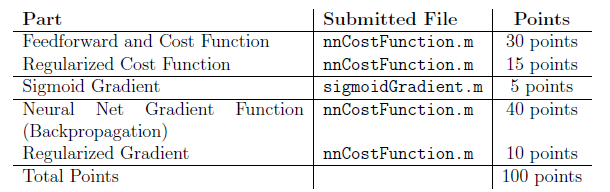

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.